# DSP Project 2

#### Signal Compression System Based On Sub-band Coding 

#### Group Members:

- Farshad Bolouri

- Brennae Stinson

- Anindita Das

## Introduction

A data acquisition system consisting of four microphones, placed near several quail habitats, documented calls from these species over time. Each of these microphones recorded calls which are audible through .wav files. The signals retrieved from the data acquisition system almost always contain background noise from the quail environments such as trees rustling, other animals, and wind. And depending on how close the quails were to the microphones when they made the calls, they could be heard clearly or very faintly. The objective of this project is to design a signal compression system based on sub-band coding. The signal will be split into four different frequency bands and each will be compressed by quantization of the samples.

clear
close all

% Variables for spectrogram function
F = 1000:10:3200;
window = 24000*0.04;
noverlap = round(0.8*window);

### Quail Call Characteristics

Before anything let's look at a quail call, analyze the characterisitics of it to learn more about it. This could help us with identifying the most important sub-bands (which sub-bands contain the most information about the quail calls).

[quailCall, fs] = audioread("quailCall.wav");
quailInfo = audioinfo("quailCall.wav")

quailInfo = struct with fields:
             Filename: '/var/Programs/GitHub/Digital-Signal-Processing/Project2/quailCall.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 24000
         TotalSamples: 25001
             Duration: 1.0417
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


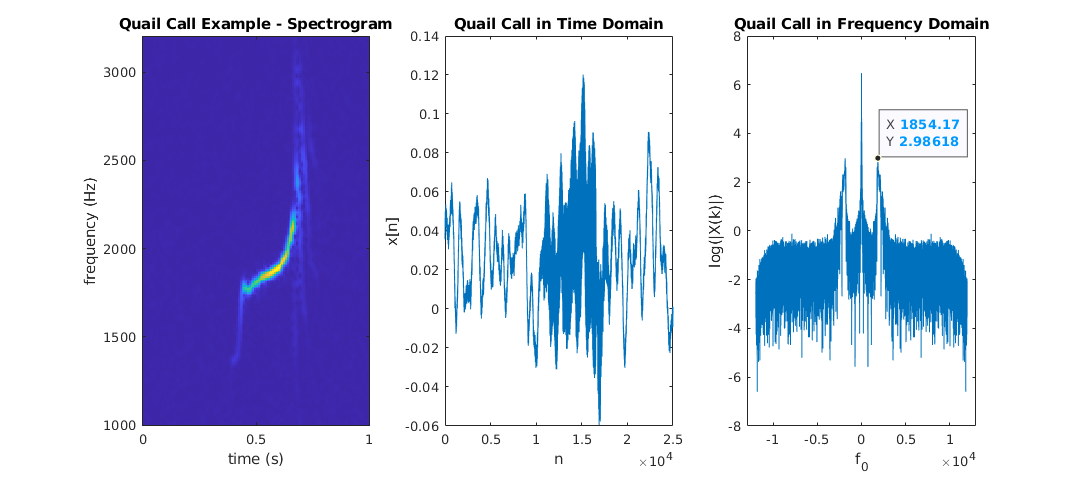

h = figure;

subplot(131);
image=spectrogram(quailCall,window,noverlap,F,fs);
imagesc(linspace(0,1,length(F)),F,abs(image))
ylabel('frequency (Hz)')
xlabel('time (s)')
set(gca,'YDir','normal')
title('Quail Call Example - Spectrogram')

subplot(132);
plot(quailCall)
xlabel('n')
ylabel('x[n]')
xlim([0 2.5e4])
title('Quail Call in Time Domain')
set(h,'Units','normalized','Position',[0 0 1 .25]); 

subplot(133);
fourierQuail = log(abs (fftshift(fft(quailCall))));             % Zero-Centered FFT
f0Quail = (-quailInfo.TotalSamples/2:quailInfo.TotalSamples/2-1)...
    /quailInfo.TotalSamples*fs;                                 % Zero-Centered Frequency Range
plot(f0Quail, fourierQuail)
ylabel('log(|X(k)|)')
xlabel('f_{0}');
xlim([-1.3e4 1.3e4])
title('Quail Call in Frequency Domain')
% axes 3
ax = gca;
chart = ax.Children(1);
datatip(chart,1854,2.986);

After inspecting the call in these plots, we concluded that even though the signature of the call is starting anywhere around the 1000-1500 Hz range up to 3200 Hz range, the main part of the call that we are intereseted in is between 1850 Hz to 2400 Hz. *(The yellow color in the spectrogram - This frequency range is what we hear and recogize as a "Quail Call" when listenning to the audio files)****.***

### Loading and Visualzing the Input Signal

[inputSig, Fs] = audioread('quailCall_middle.wav');
inputInfo = audioinfo('quailCall_middle.wav')

inputInfo = struct with fields:
             Filename: '/var/Programs/GitHub/Digital-Signal-Processing/Project2/quailCall_middle.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 24000
         TotalSamples: 240001
             Duration: 10.0000
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


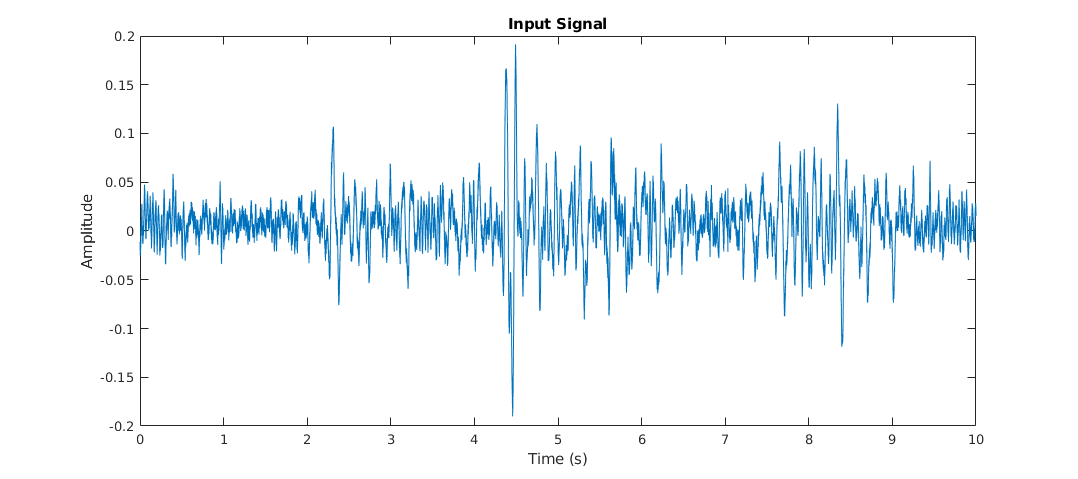

timeInput = linspace(0, inputInfo.Duration, inputInfo.TotalSamples);
h = figure;
plot(timeInput, inputSig)
title('Input Signal')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
set(h,'Units','normalized','Position',[0 0 1 .25]);

Now let's listen to this signal:

*(If you would prefer to not listen to this audio file, don't run this section or comment it out :) )*

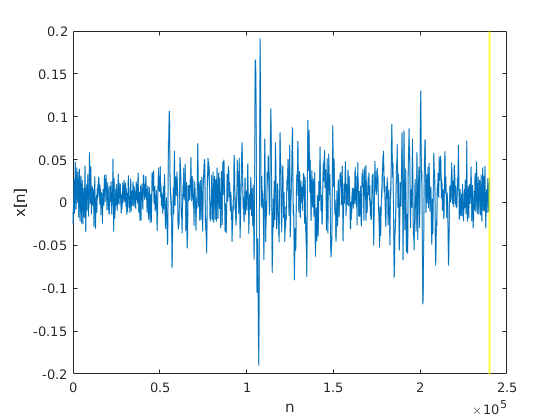

player = audioplayer(inputSig,Fs);
figure
plot(inputSig)
xlabel('n')
ylabel('x[n]')
pause(2)
hold on
Bar = xline(0,'Color','yellow','LineWidth',1.5);
play(player);
for i = 1:length(inputSig)/2400
     set(Bar,'Value',Bar.Value+2400);
     pause(.1);
end

The call can be heard in the middle of the audio file as demonstrated above.

Let's look at the signal in the frequency domain:

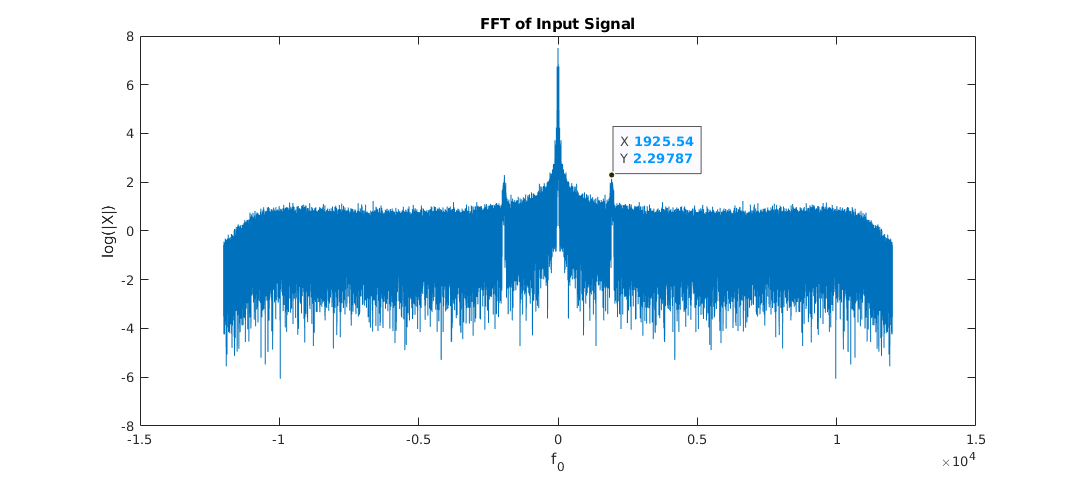

h = figure;
inputFFT = log(abs (fftshift(fft(inputSig))));                  % Zero-Centered FFT
f0Input = (-inputInfo.TotalSamples/2:inputInfo.TotalSamples/2-1)...
    /inputInfo.TotalSamples*Fs;                                 % Zero-Centered Frequency Range
plot(f0Input, inputFFT)
title('FFT of Input Signal');
ylabel('log(|X|)')
xlabel('f_{0}');
ax = gca;
chart = ax.Children(1);
datatip(chart,1926,2.298);
set(h,'Units','normalized','Position',[0 0 1 0.25]);

As you can see the strength of the quail call here is not as much as the quail call demonstrated before. That's just due to the quail being farther away from the microphone in the time of the recording. But we still can clearly identify our target frequency.

## The Encoder

The encoder consists of an analysis filter band and a quantizer per subband. The analysis filter bank consists of concatenated lowpass and highpass filters, where ${\mathrm{H}}_0 \left(z\right)$ is a lowpass filter and ${\mathrm{H}}_1 \left(z\right)$ a highpass filter, see figure below. The structure provides a finer frequency resolution at lower frequencies. 

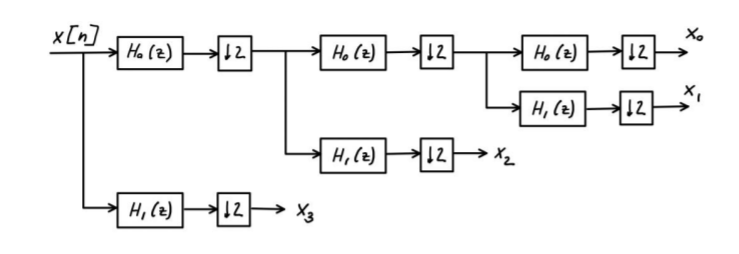

### Designing the Filters

#### ${\mathrm{H}}_0 \left(z\right)$:

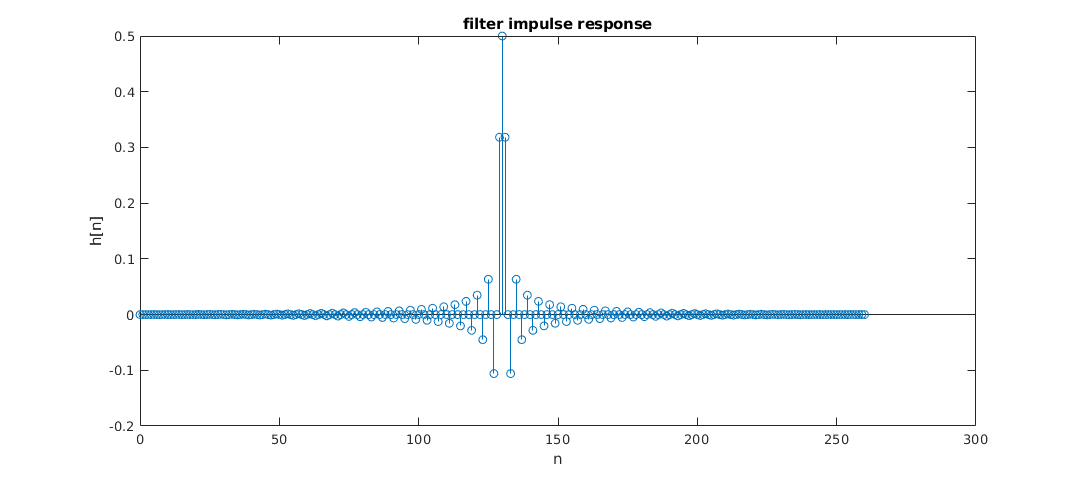

% FIR Window Lowpass filter designed using the FIR1 function.

% All frequency values are in Hz.

Fpass = 5800;              % Passband Frequency
Fstop = 6200;              % Stopband Frequency
Dpass = 0.057501127785;    % Passband Ripple
Dstop = 0.00031622776602;  % Stopband Attenuation
flag  = 'scale';           % Sampling Flag

% Calculate the order from the parameters using KAISERORD.
[N,Wn,BETA,TYPE] = kaiserord([Fpass Fstop]/(Fs/2), [1 0], [Dstop Dpass]);

% Calculate the coefficients using the FIR1 function.
hLP  = fir1(N, Wn, TYPE, kaiser(N+1, BETA), flag);

% graph filter impulse response
graph = figure;
stem(0:length(hLP)-1,hLP)
xlabel('n')
ylabel('h[n]')
title('filter impulse response')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

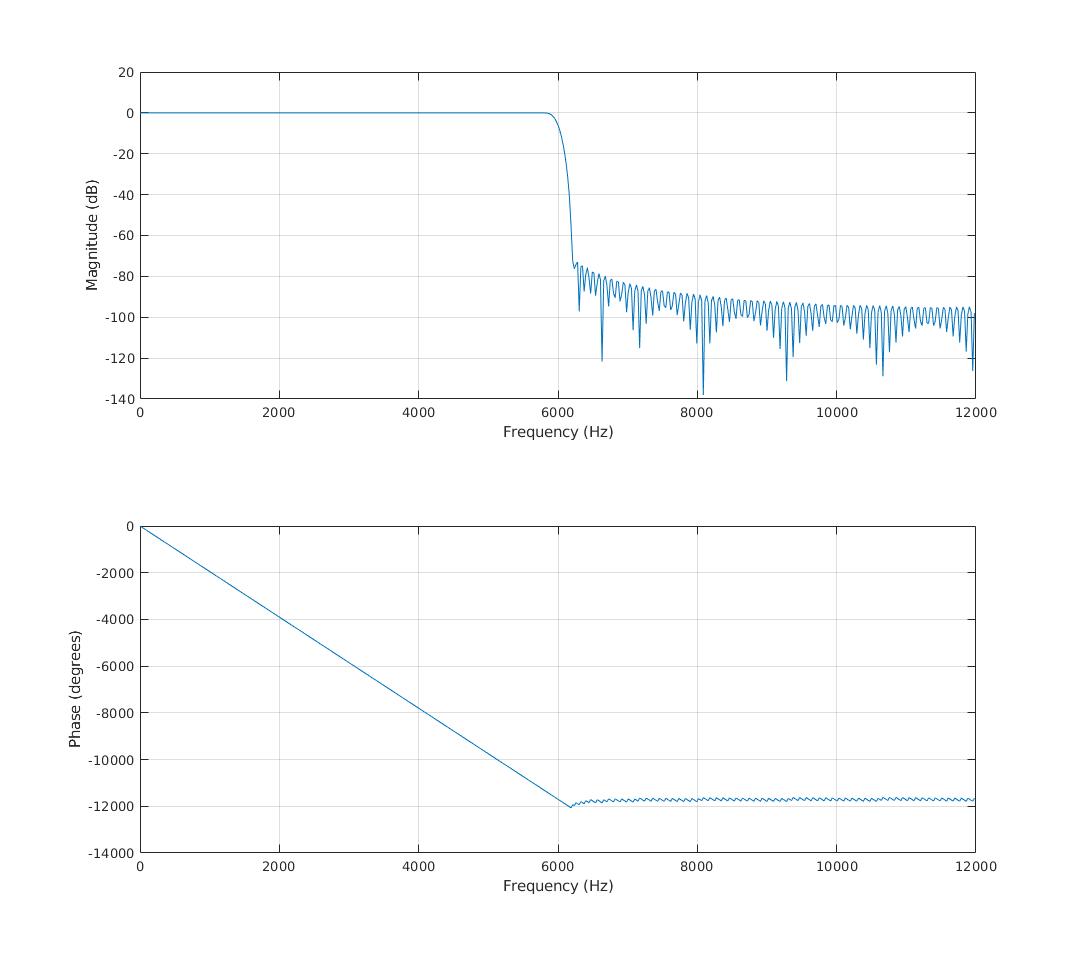

% graph filter frequency response
graph = figure;
freqz(hLP,1,[],Fs)
set(graph,'Units','normalized','Position',[0 0 1 0.5]);

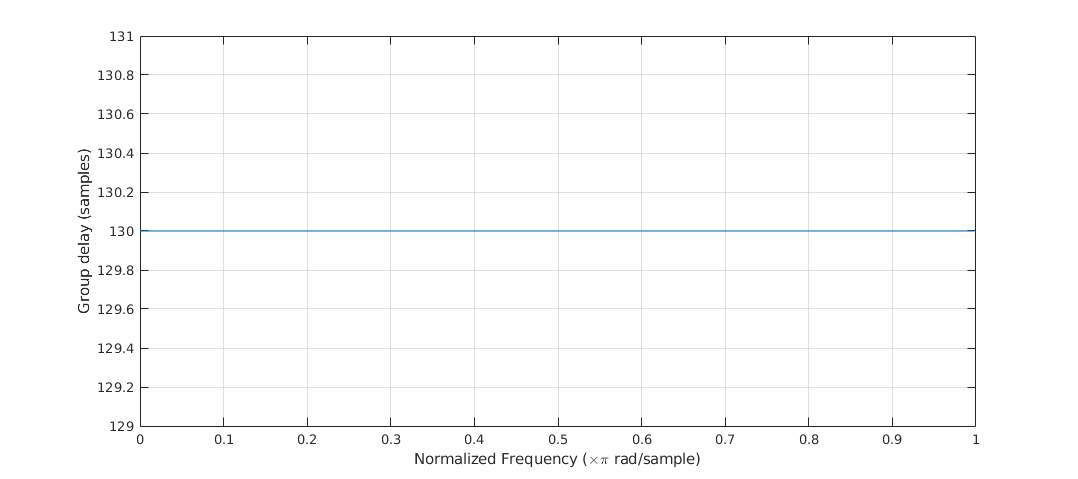

% graph filter group delay
graph = figure;
grpdelay(hLP,1)
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

We chose our passband ripple to be 1 dB because we didn't want too much fluctuations in the frequencies that we are trying to keep. We put the stopband attenuation to 70 dB  as we found it to be enough to remove the frequencies that we don't want.

Our $f_s$ is at 24000 Hz as this is the sampling frequency of our input signal.

We set our $f_c$ to 6000 Hz and the way we calculated this $f_c$ was : $\frac{\frac{f_s }{2}}{M}=\frac{\frac{24000}{2}\;\textrm{Hz}}{2}=6000\;\textrm{Hz}$. ($M$ being the decimating factor.)

We used a Kaiser window for designing the FIR filter, as we had the option to design the filter with "Minimum Order" conditions while maintaining the desired attributes of the filter. The order of the filter was calculated to be **260**.

#### ${\mathrm{H}}_1 \left(z\right)$:

As we are trying split the input signal to two signals, one containing the lower half of the representable frequencies, and the second one, the upper half of the frequencies, we need to design our first highpass filter with the same conditions as our first lowpass to provide the best results.

Here's the cooresponding Highpass filter:

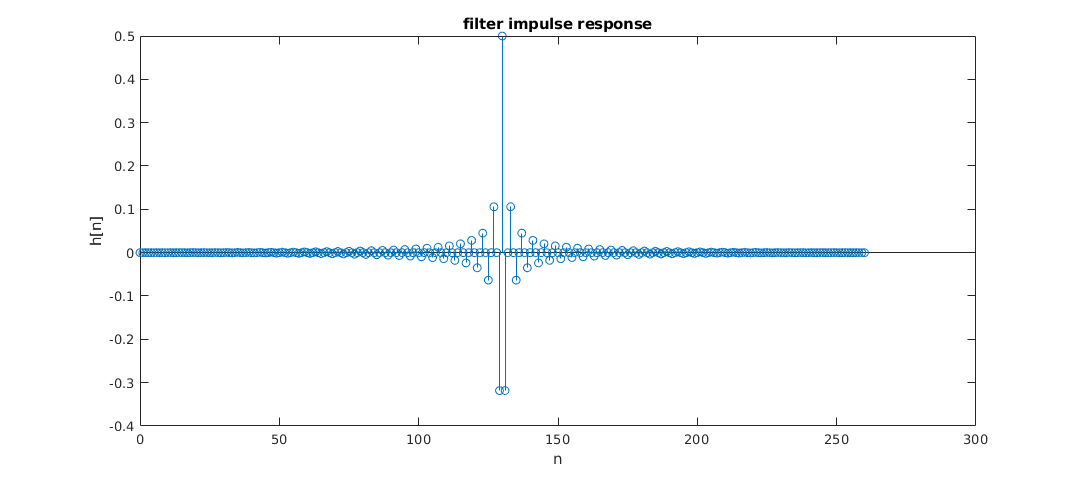

Fstop = 5800;              % Stopband Frequency
Fpass = 6200;              % Passband Frequency
Dstop = 0.00031622776602;  % Stopband Attenuation
Dpass = 0.057501127785;    % Passband Ripple
flag  = 'scale';           % Sampling Flag

% Calculate the order from the parameters using KAISERORD.
[N,Wn,BETA,TYPE] = kaiserord([Fstop Fpass]/(Fs/2), [0 1], [Dpass Dstop]);

% Calculate the coefficients using the FIR1 function.
hHP  = fir1(N, Wn, TYPE, kaiser(N+1, BETA), flag);

% graph filter impulse response
graph = figure;
stem(0:length(hHP)-1,hHP)
xlabel('n')
ylabel('h[n]')
title('filter impulse response')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

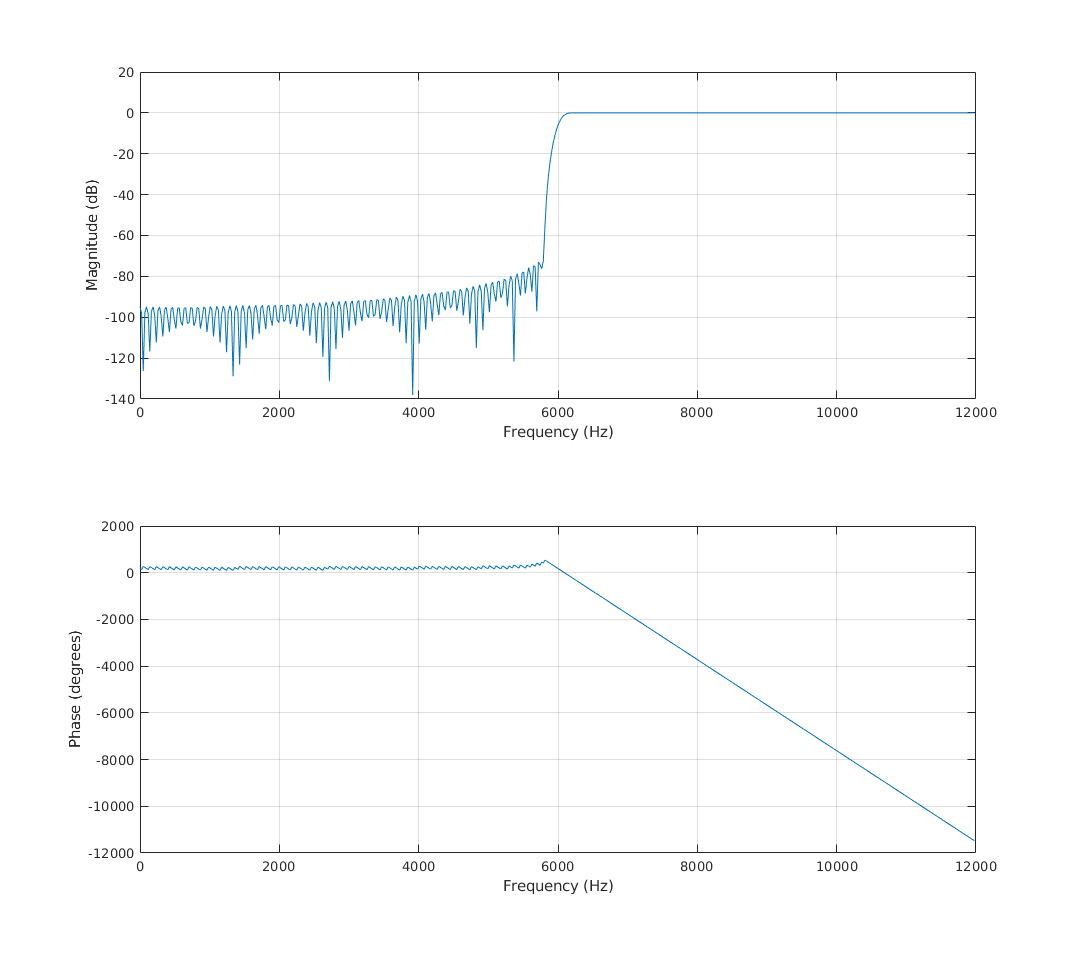

% graph filter frequency response
graph = figure;
freqz(hHP,1,[],Fs)
set(graph,'Units','normalized','Position',[0 0 1 0.5]);

% graph filter group delay
graph = figure;
grpdelay(hHP,1)
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

By looking at the group delays of the both filters we can say we have a delay of 130 samples.

hHP = 1.415*hHP;
hLP = 1.415*hLP;

delay = 130;

### Decimation using the Filters

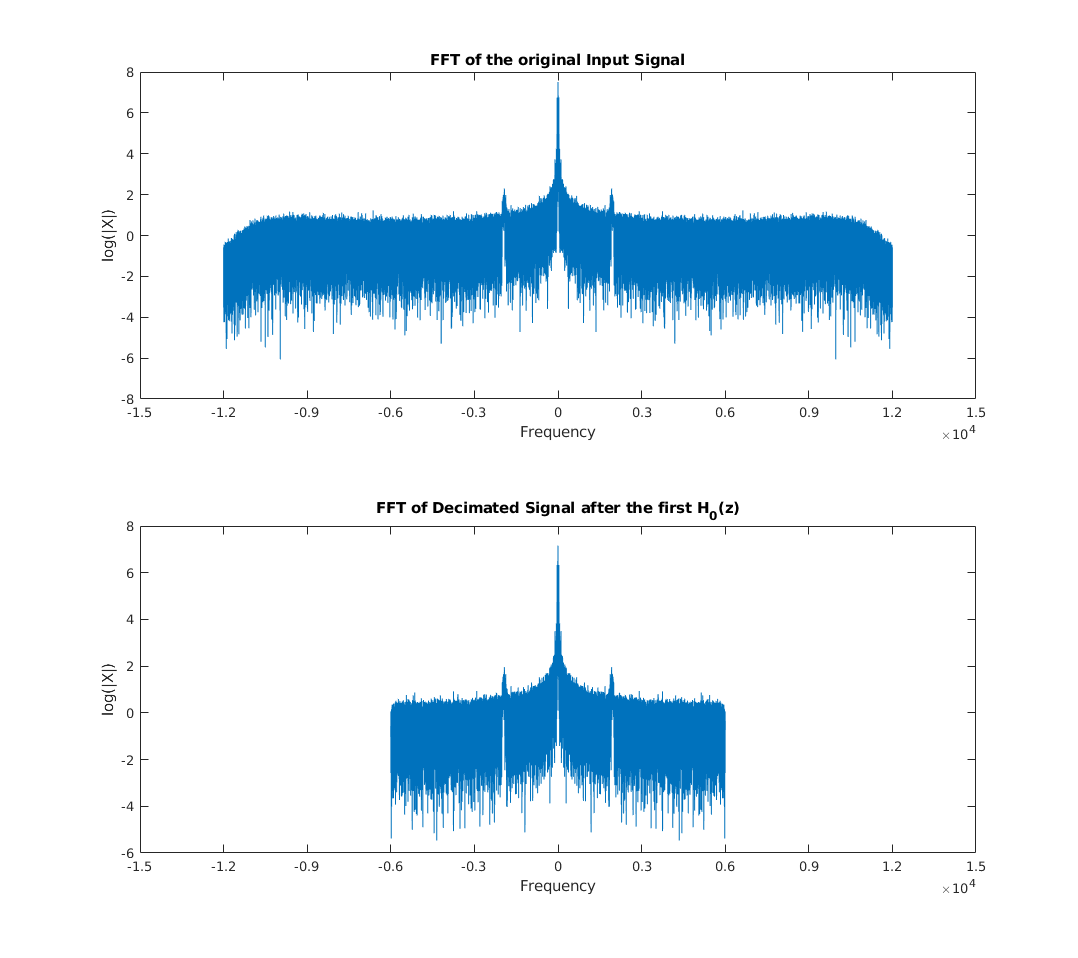

filteredSigLP1 = filter(hLP, 1, inputSig);

% Adjusting for delay
inputSig_wDelay = inputSig(1:end-delay);
timeInput_wDelay = timeInput(1:end-delay);
filteredSigLP1_wDelay = filteredSigLP1;
filteredSigLP1_wDelay(1:delay) = [];

M = 2;   % Decimating Factor
decimatedSigLP1= filteredSigLP1_wDelay(1:M:end);
timeDecimatedSigLP1 = linspace(0, inputInfo.Duration, length(decimatedSigLP1));

audiowrite("decimatedSigLP1.wav", decimatedSigLP1, Fs/2);

decimatedSigLP1FFT = log(abs(fftshift(fft(decimatedSigLP1))));     % Zero-Centered FFT
decimatedSigLP1F = (-length(decimatedSigLP1)/2:...
    length(decimatedSigLP1)/2-1)...
    /length(decimatedSigLP1)*Fs/2;             % Zero-Centered Frequency Range

graph = figure;
subplot(212)
plot(decimatedSigLP1F, decimatedSigLP1FFT)
title('FFT of Decimated Signal after the first H_0(z)');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
subplot(2,1,1)              
plot(f0Input, inputFFT)
title('FFT of the original Input Signal');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.5]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)

*You can see how the frequency range has changed from [-12000  12000 Hz] to [-6000 6000 Hz] which represents the lower frequency band of the signal. As you can see we are still seeing the quail call signature as it exists in this frequency range.*

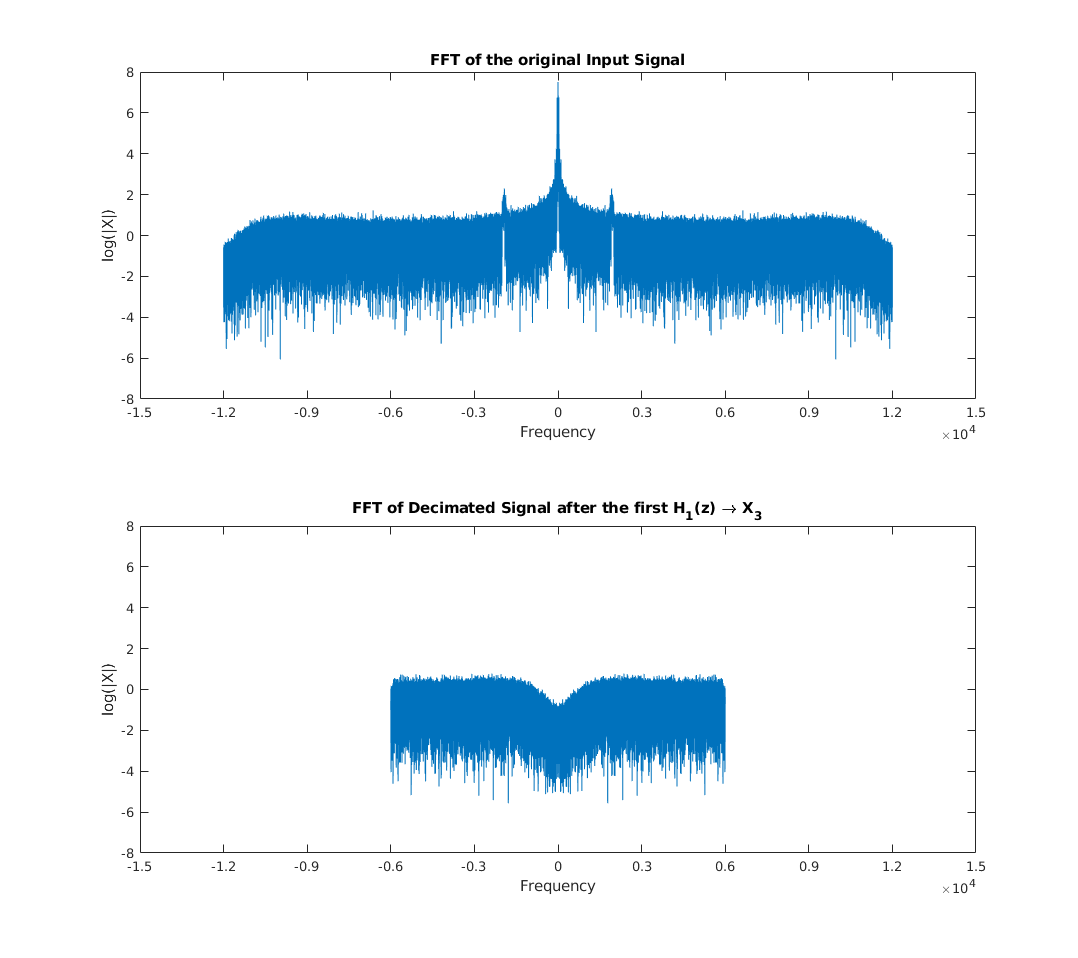

filteredSigHP1 = filter(hHP, 1, inputSig);

% Adjusting for delay
filteredSigHP1_wDelay = filteredSigHP1;
filteredSigHP1_wDelay(1:delay) = [];

decimatedSigHP1= filteredSigHP1_wDelay(1:M:end);

audiowrite("decimatedSigHP1.wav", decimatedSigHP1, Fs/2);

decimatedSigHP1FFT = log(abs(fftshift(fft(decimatedSigHP1))));     % Zero-Centered FFT
decimatedSigHP1F = (-length(decimatedSigHP1)/2:...
    length(decimatedSigHP1)/2-1)...
    /length(decimatedSigHP1)*Fs/2;             % Zero-Centered Frequency Range

graph = figure;
subplot(212)
plot(decimatedSigHP1F, decimatedSigHP1FFT)
title('FFT of Decimated Signal after the first H_1(z) \rightarrow X_3');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
subplot(2,1,1)
plot(f0Input, inputFFT)
title('FFT of the original Input Signal');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.5]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)

You can see how the frequency range has now changed same as the last filtering process. However the frequencies shown above are not actually representing the frequencies [-6000 6000] of the actual input signal.  You are seeing the frequencies from 12-24 kHz being shifted to -12-0 kHz and those from -24- -12 kHz being shifted to 0-12 kHz.

They're actually representing the frequencies [-12000 -6000] and [6000 12000] as this decimation process is actually preserving the higher frequencies. The graph below demonstrates this better.

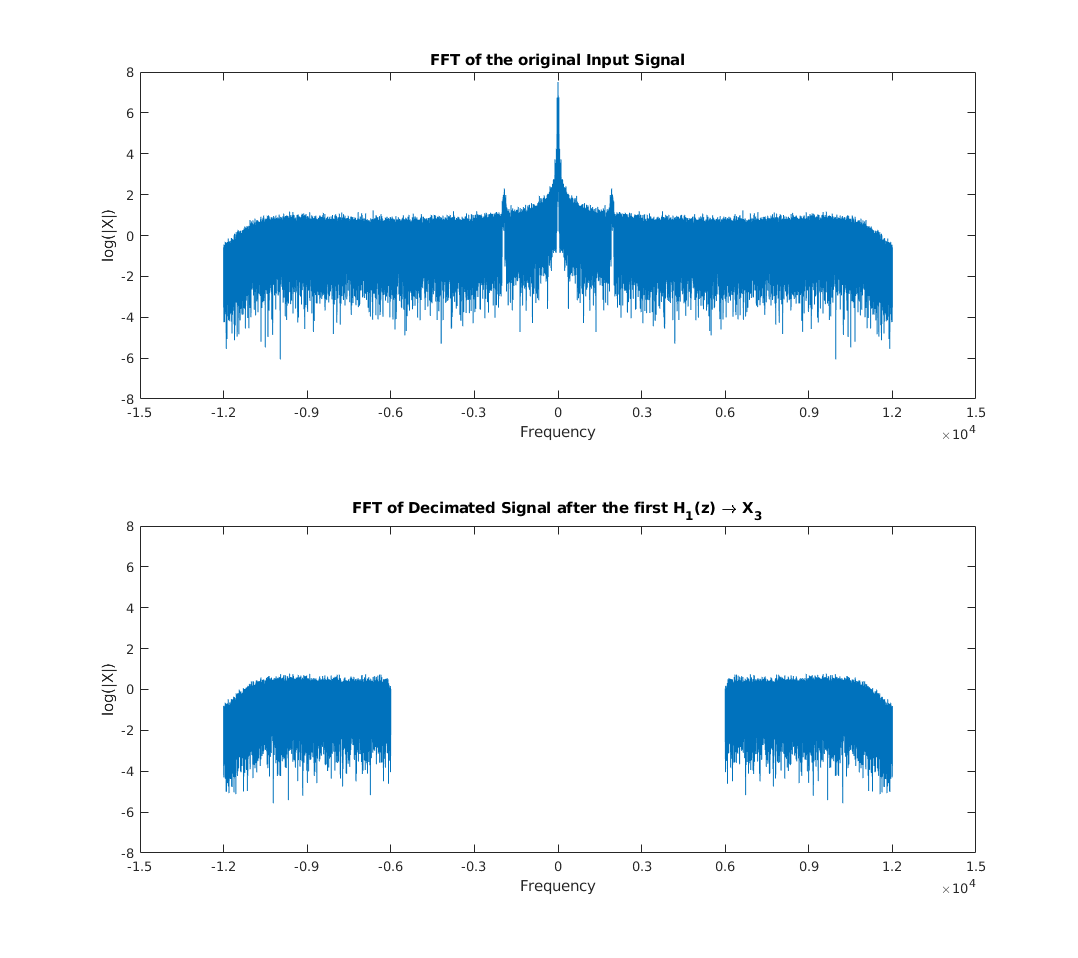

graph = figure;
subplot(212)
plot(decimatedSigHP1F(1:ceil(end/2)) - Fs/2/2, decimatedSigHP1FFT(ceil(end/2):-1:1))
hold on
plot(decimatedSigHP1F(ceil(end/2):end) + Fs/2/2, decimatedSigHP1FFT(end:-1:ceil(end/2)), 'color', [0, 0.4470, 0.7410])
title('FFT of Decimated Signal after the first H_1(z) \rightarrow X_3');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
hold off
subplot(2,1,1)
plot(f0Input, inputFFT)
title('FFT of the original Input Signal');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.5]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)

You can see the first half of the decimated signal is corresponding to frequencies [-12000 -6000] and second half [6000 12000].

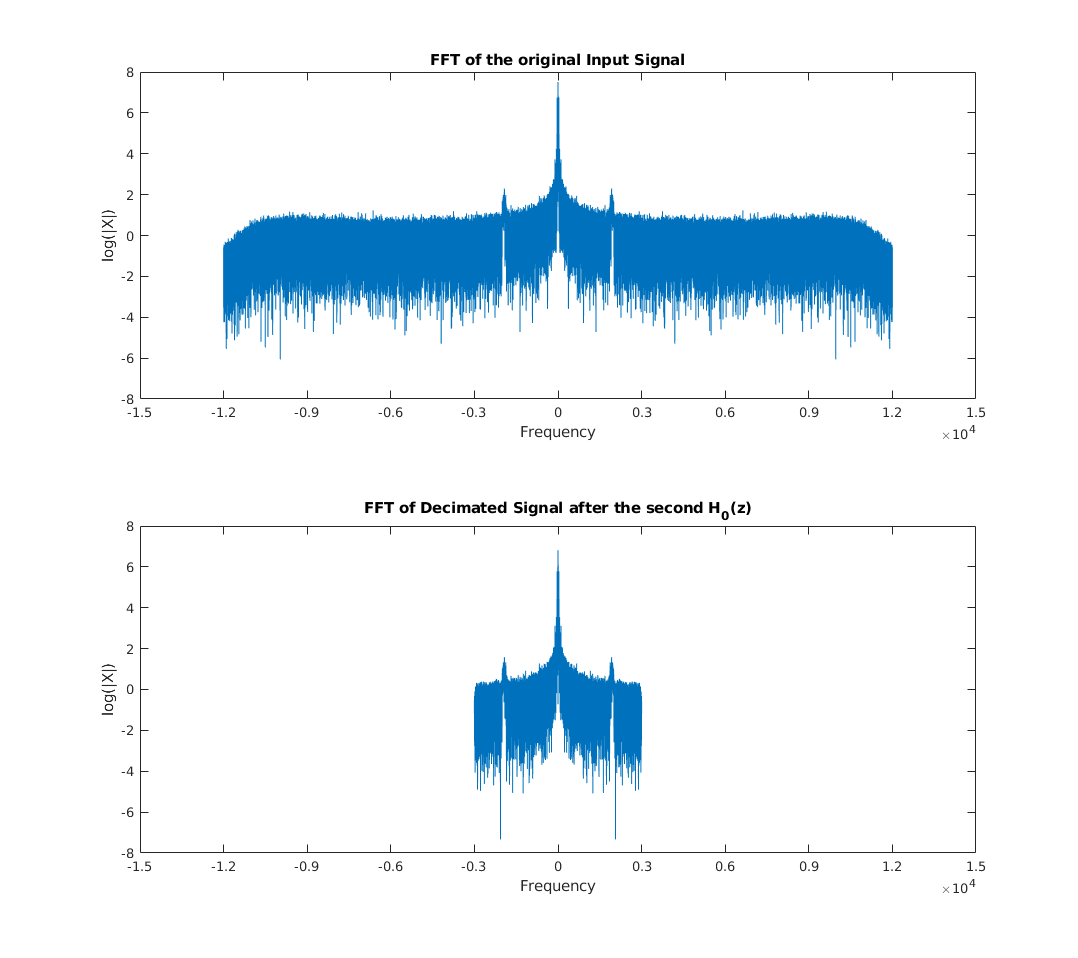

filteredSigLP2 = filter(hLP, 1, decimatedSigLP1);

% Adjusting for delay
decimatedSigLP1_wDelay = decimatedSigLP1(1:end-delay);
timeDecimatedSigLP1_wDelay = timeDecimatedSigLP1(1:end-delay);
filteredSigLP2_wDelay = filteredSigLP2;
filteredSigLP2_wDelay(1:delay) = [];

decimatedSigLP2= filteredSigLP2_wDelay(1:M:end);
timeDecimatedSigLP2 = linspace(0, inputInfo.Duration, length(decimatedSigLP2));

audiowrite("decimatedSigLP2.wav", decimatedSigLP2, Fs/4);

decimatedSigLP2FFT = log(abs(fftshift(fft(decimatedSigLP2))));     % Zero-Centered FFT
decimatedSigLP2F = (-length(decimatedSigLP2)/2:...
    length(decimatedSigLP2)/2-1)...
    /length(decimatedSigLP2)*Fs/4;             % Zero-Centered Frequency Range

graph = figure;
subplot(212)
plot(decimatedSigLP2F, decimatedSigLP2FFT)
title('FFT of Decimated Signal after the second H_0(z)');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
subplot(2,1,1)
plot(f0Input, inputFFT)
title('FFT of the original Input Signal');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.5]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)

*You can see how the frequency range has changed from [-6000  6000 Hz] to [-3000 3000 Hz] which represents the lower frequency band of the decimated signal. As you can see we are still seeing the quail call signature as it exists in this frequency range.*

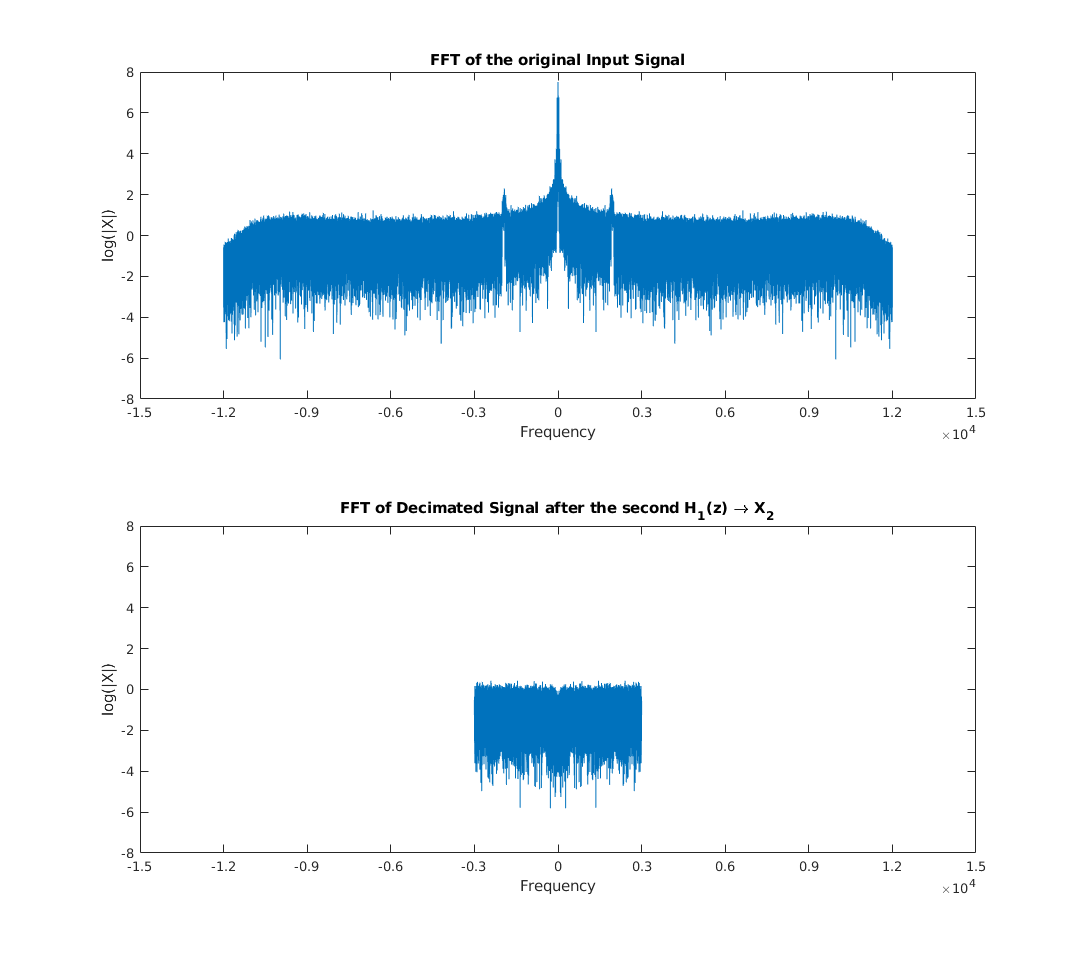

filteredSigHP2 = filter(hHP, 1, decimatedSigLP1);

% Adjusting for delay
filteredSigHP2_wDelay = filteredSigHP2;
filteredSigHP2_wDelay(1:delay) = [];

decimatedSigHP2= filteredSigHP2_wDelay(1:M:end);

audiowrite("decimatedSigHP2.wav", decimatedSigHP2, Fs/4);

decimatedSigHP2FFT = log(abs(fftshift(fft(decimatedSigHP2))));     % Zero-Centered FFT
decimatedSigHP2F = (-length(decimatedSigHP2)/2:...
    length(decimatedSigHP2)/2-1)...
    /length(decimatedSigHP2)*Fs/4;             % Zero-Centered Frequency Range

graph = figure;
subplot(212)
plot(decimatedSigHP2F, decimatedSigHP2FFT)
title('FFT of Decimated Signal after the second H_1(z) \rightarrow X_2');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
subplot(2,1,1)
plot(f0Input, inputFFT)
title('FFT of the original Input Signal');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.5]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)

Again the same scenario as before is happening here. The graphs below show what frequencies are actually being represented after the second highpass decimation.

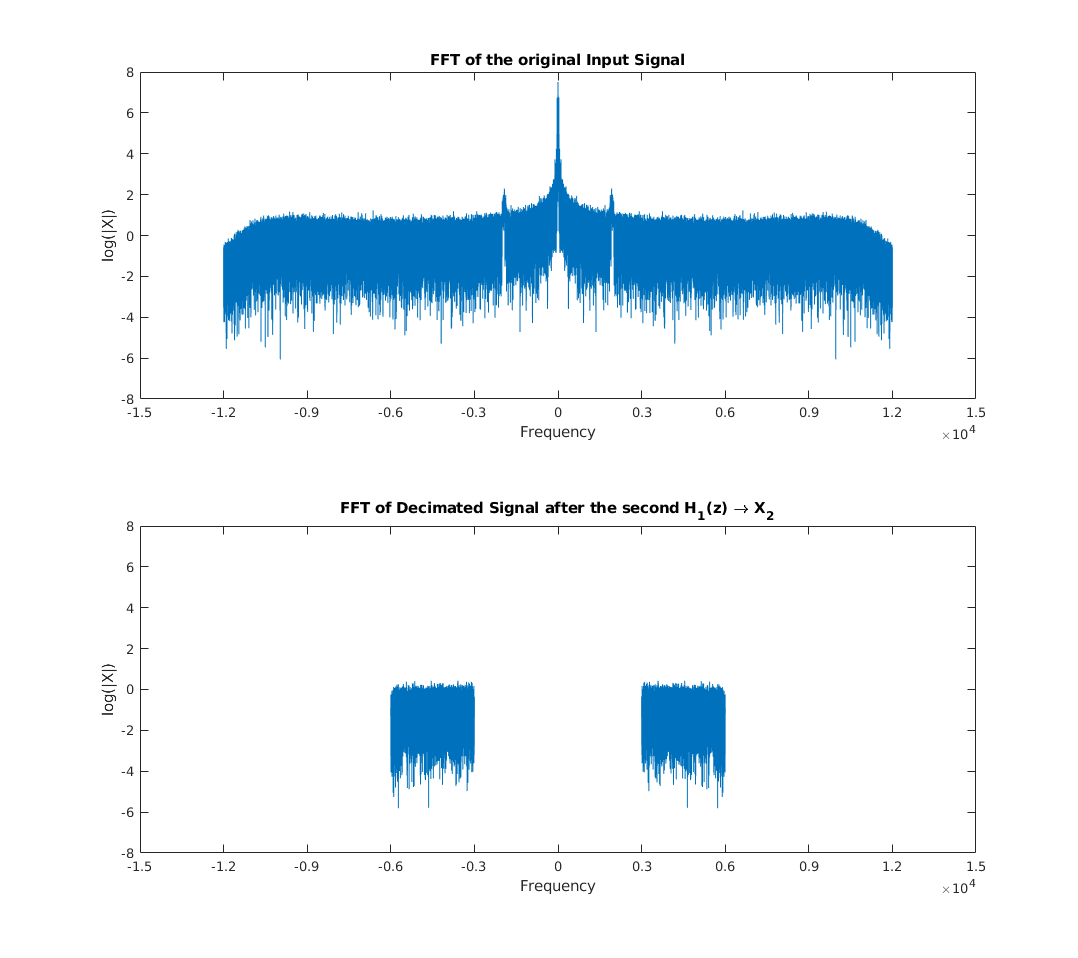

graph = figure;
subplot(212)
plot(decimatedSigHP2F(1:ceil(end/2)) - Fs/4/2, decimatedSigHP2FFT(ceil(end/2):-1:1))
hold on
plot(decimatedSigHP2F(ceil(end/2):end) + Fs/4/2, decimatedSigHP2FFT(end:-1:ceil(end/2)), 'color', [0, 0.4470, 0.7410])
title('FFT of Decimated Signal after the second H_1(z) \rightarrow X_2');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
hold off
subplot(2,1,1)
plot(f0Input, inputFFT)
title('FFT of the original Input Signal');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.5]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)

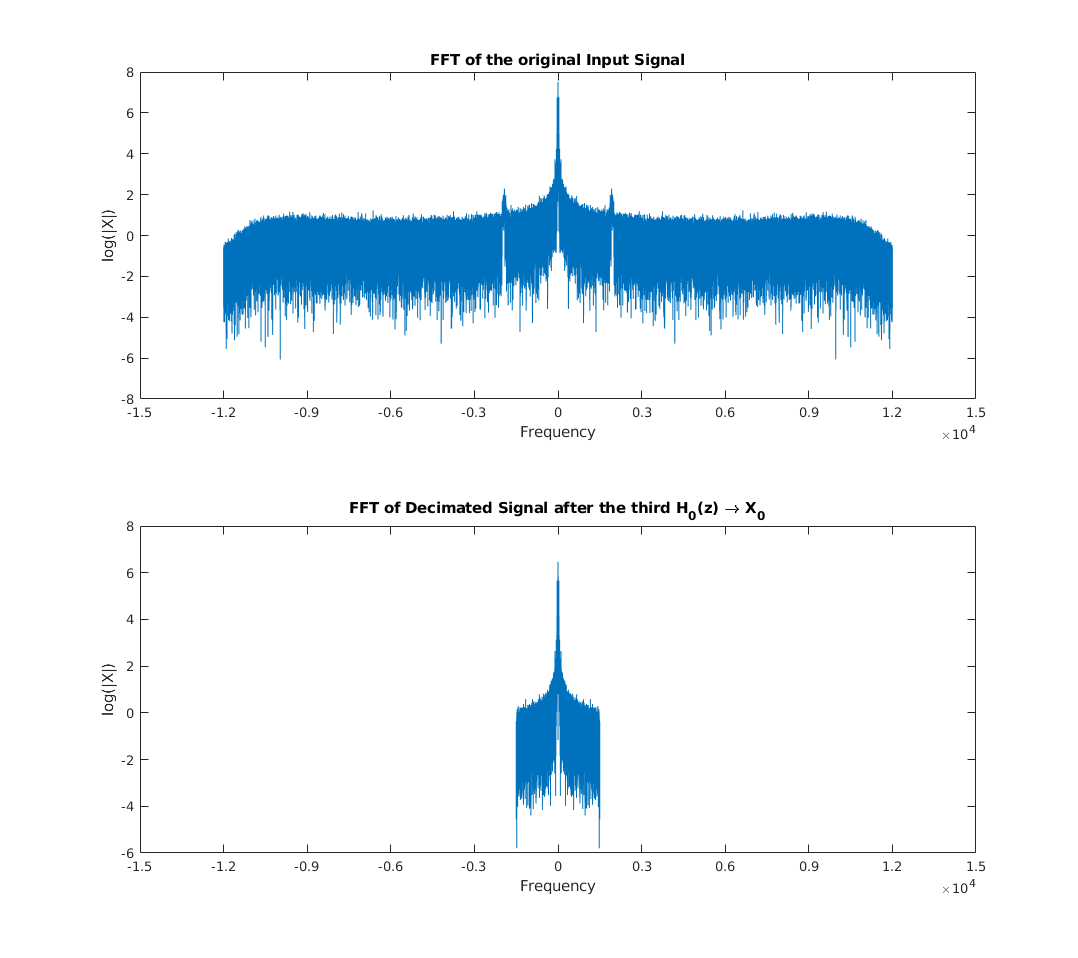

filteredSigLP3 = filter(hLP, 1, decimatedSigLP2);

% Adjusting for delay
decimatedSigLP2_wDelay = decimatedSigLP2(1:end-delay);
timeDecimatedSigLP2_wDelay = timeDecimatedSigLP2(1:end-delay);
filteredSigLP3_wDelay = filteredSigLP3;
filteredSigLP3_wDelay(1:delay) = [];

decimatedSigLP3 = filteredSigLP3_wDelay(1:M:end);
timeDecimatedSigLP3 = linspace(0, inputInfo.Duration, length(decimatedSigLP3));

audiowrite("decimatedSigLP3.wav", decimatedSigLP3, Fs/4/2);

decimatedSigLP3FFT = log(abs(fftshift(fft(decimatedSigLP3))));     % Zero-Centered FFT
decimatedSigLP3F = (-length(decimatedSigLP3)/2:...
    length(decimatedSigLP3)/2-1)...
    /length(decimatedSigLP3)*Fs/4/2;             % Zero-Centered Frequency Range

graph = figure;
subplot(212)
plot(decimatedSigLP3F, decimatedSigLP3FFT)
title('FFT of Decimated Signal after the third H_0(z) \rightarrow X_0');
ylabel('log(|X|)')
xlabel('Frequency'); 
xlim([-15000 15000])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
subplot(2,1,1)
plot(f0Input, inputFFT)
title('FFT of the original Input Signal');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.5]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)

*You can see how the frequency range has now changed from [-3000  3000 Hz] to [-1500 1500 Hz] which represents the lower frequency band of the second decimated signal. However, now we cannot see the quail signature anymore and this is expected from our previous analysis. In the begining we showed that the frequency range for the quail calls are between 1850 Hz to 2400 Hz, therefore it makes sense that we cannot see the signatures in the  [-1500 1500 Hz]  range. *

*We should be able to see the signatures in the higher frequency band after applying the third *$H_1 \left(z\right)$. The figures below should demonstrate this:

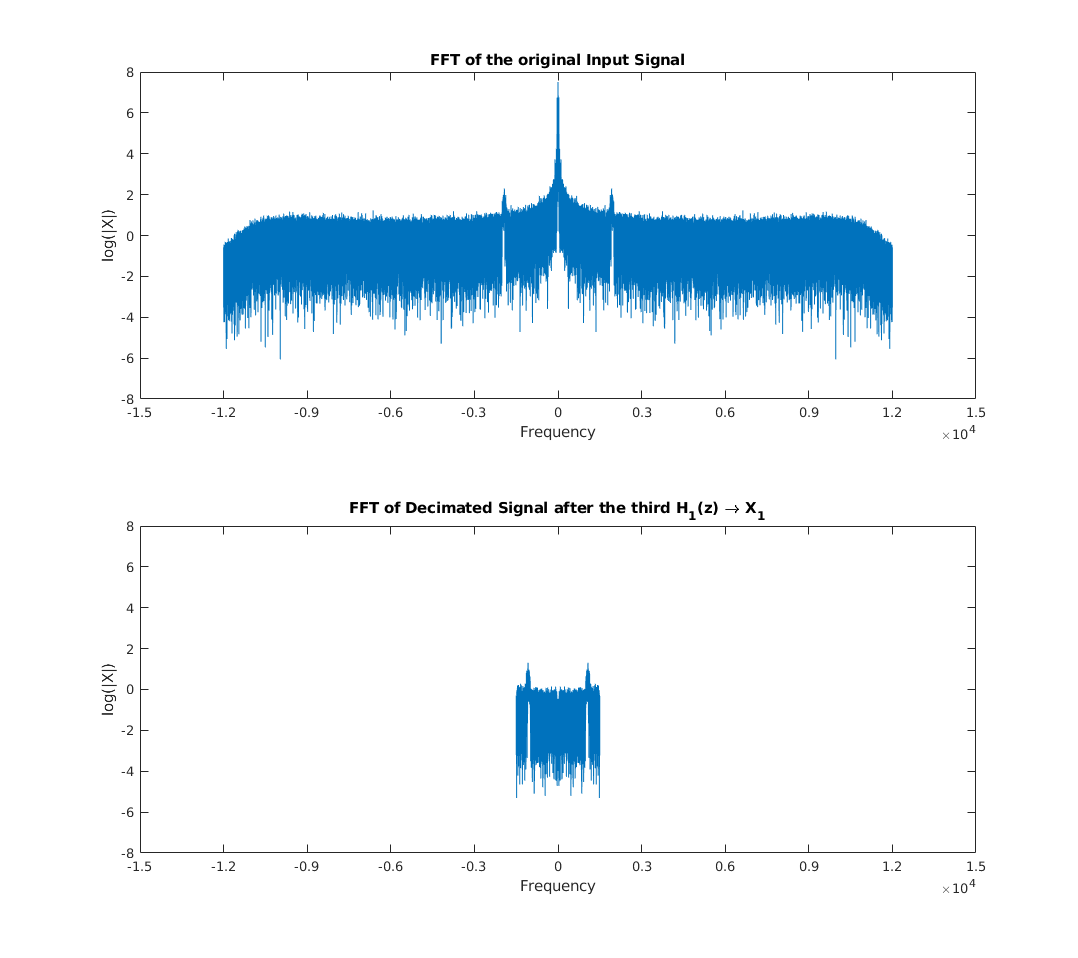

filteredSigHP3 = filter(hHP, 1, decimatedSigLP2);

% Adjusting for delay
filteredSigHP3_wDelay = filteredSigHP3;
filteredSigHP3_wDelay(1:delay) = [];

decimatedSigHP3= filteredSigHP3_wDelay(1:M:end);

audiowrite("decimatedSigHP3.wav", decimatedSigHP3, Fs/4/2);

decimatedSigHP3FFT = log(abs(fftshift(fft(decimatedSigHP3))));     % Zero-Centered FFT
decimatedSigHP3F = (-length(decimatedSigHP3)/2:...
    length(decimatedSigHP3)/2-1)...
    /length(decimatedSigHP3)*Fs/4/2;             % Zero-Centered Frequency Range

graph = figure;
subplot(212)
plot(decimatedSigHP3F, decimatedSigHP3FFT)
title('FFT of Decimated Signal after the third H_1(z) \rightarrow X_1');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
subplot(2,1,1)
plot(f0Input, inputFFT)
title('FFT of the original Input Signal');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.5]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)

Notice now we can see signatures after the third highpass decimation which we couldn't see before after the lowpass decimation.

The graphs below show what frequencies are actually being represented after the third highpass decimation.

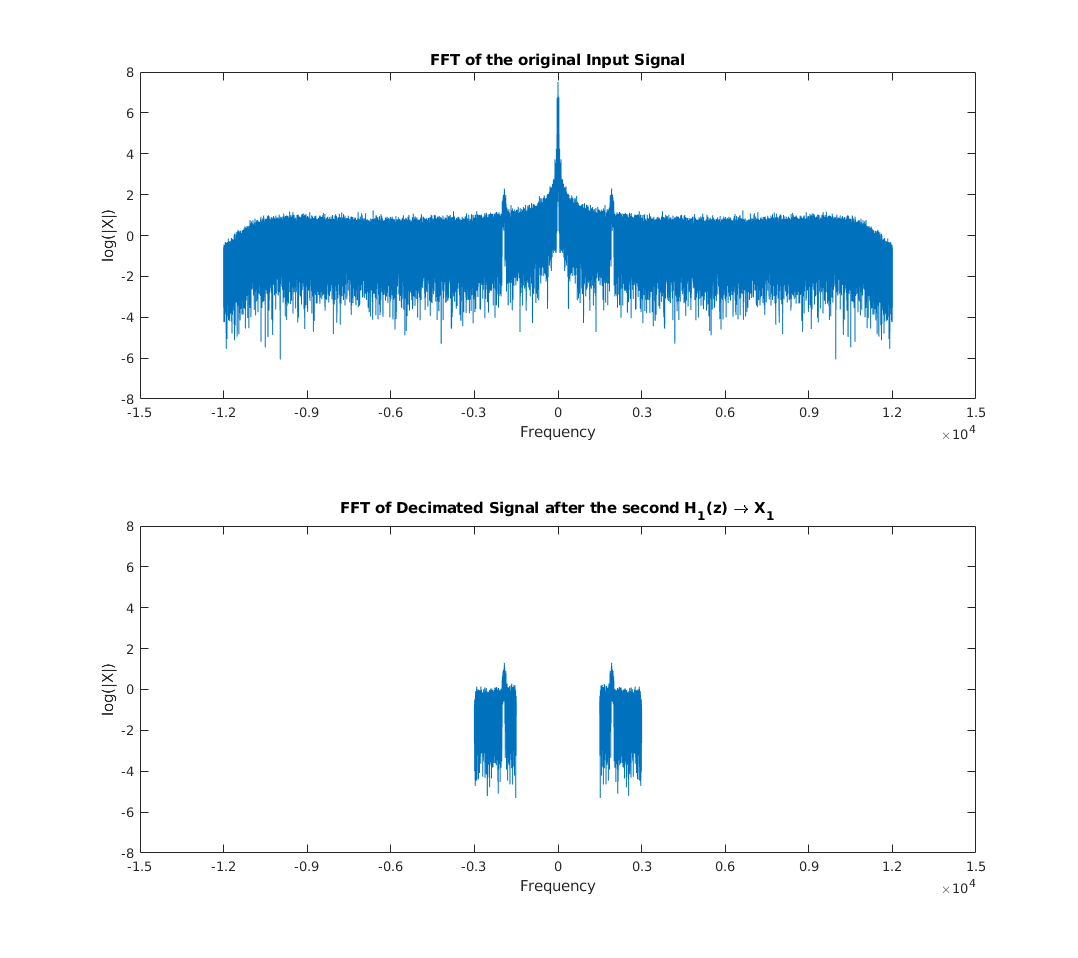

graph = figure;
subplot(212)
plot(decimatedSigHP3F(1:ceil(end/2)) - Fs/4/4, decimatedSigHP3FFT(ceil(end/2):-1:1))
hold on
plot(decimatedSigHP3F(ceil(end/2):end) + Fs/4/4, decimatedSigHP3FFT(end:-1:ceil(end/2)), 'color', [0, 0.4470, 0.7410])
title('FFT of Decimated Signal after the second H_1(z) \rightarrow X_1');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
hold off
subplot(2,1,1)
plot(f0Input, inputFFT)
title('FFT of the original Input Signal');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.5]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)

### Evaluating the Encoder

In order to verify that our Encoder is doing a good job we are going to put all our results back together to see if we still get to our original signal. This process can show us if we are creating any distortions in the encoding process.

Let's start with interpolating $X_1$

L = 2;

upsampledSigHP3(1:L:L*length(decimatedSigHP3)) = decimatedSigHP3;

Let's compare the FFT of $X_1$ and the upsampled version:

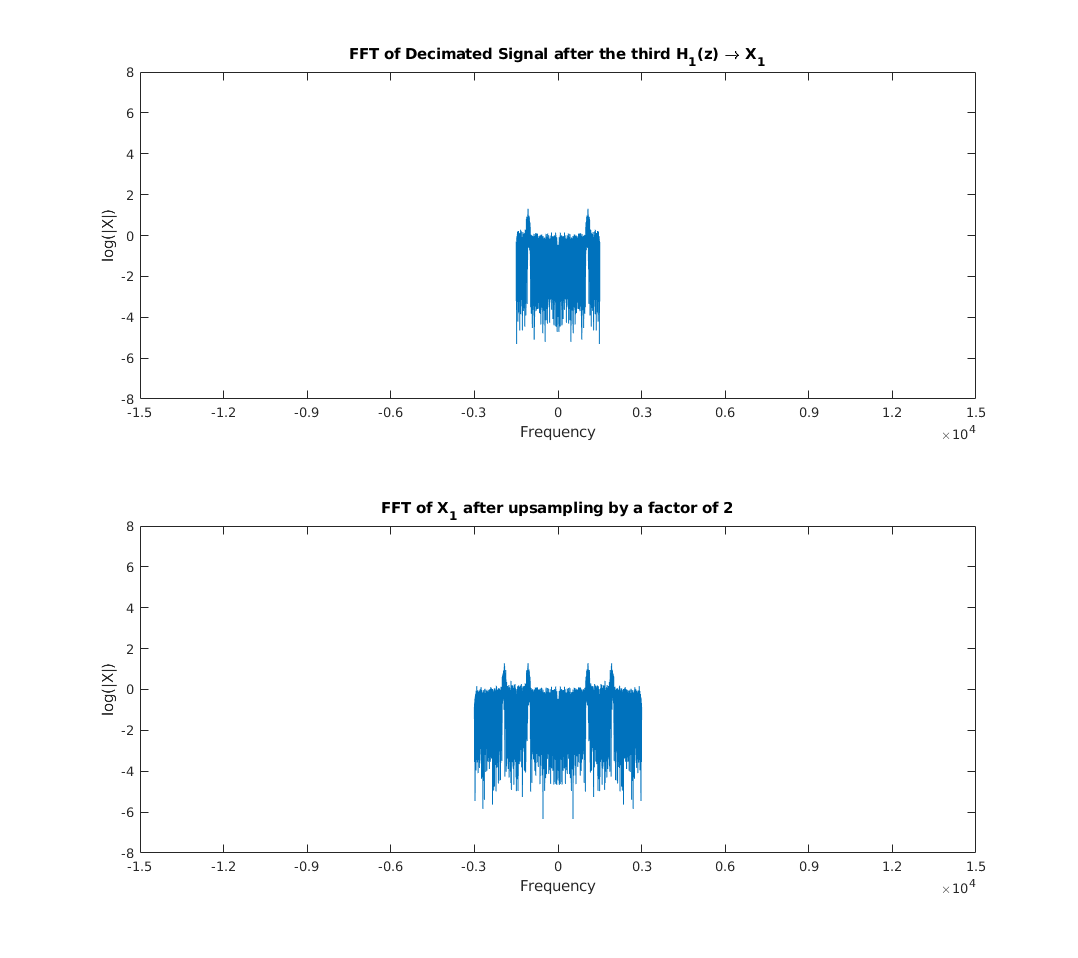

upsampledSigHP3FFT = log(abs(fftshift(fft(upsampledSigHP3))));     % Zero-Centered FFT
upsampledSigHP3F = (-length(upsampledSigHP3)/2:...
    length(upsampledSigHP3)/2-1)/length(upsampledSigHP3)...
    *Fs/8*L;                           % Zero-Centered Frequency Range 

graph = figure;
subplot(211)
plot(decimatedSigHP3F, decimatedSigHP3FFT)
title('FFT of Decimated Signal after the third H_1(z) \rightarrow X_1');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
subplot(2,1, 2)
plot(upsampledSigHP3F, upsampledSigHP3FFT)
title('FFT of X_1 after upsampling by a factor of 2');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.5]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
xlim([-15000 15000])
ylim([-8 8])

Here you can see the effect of upsampling on the frequency domain. Now we interpolate the upsampled signal with the same HighPass filter.

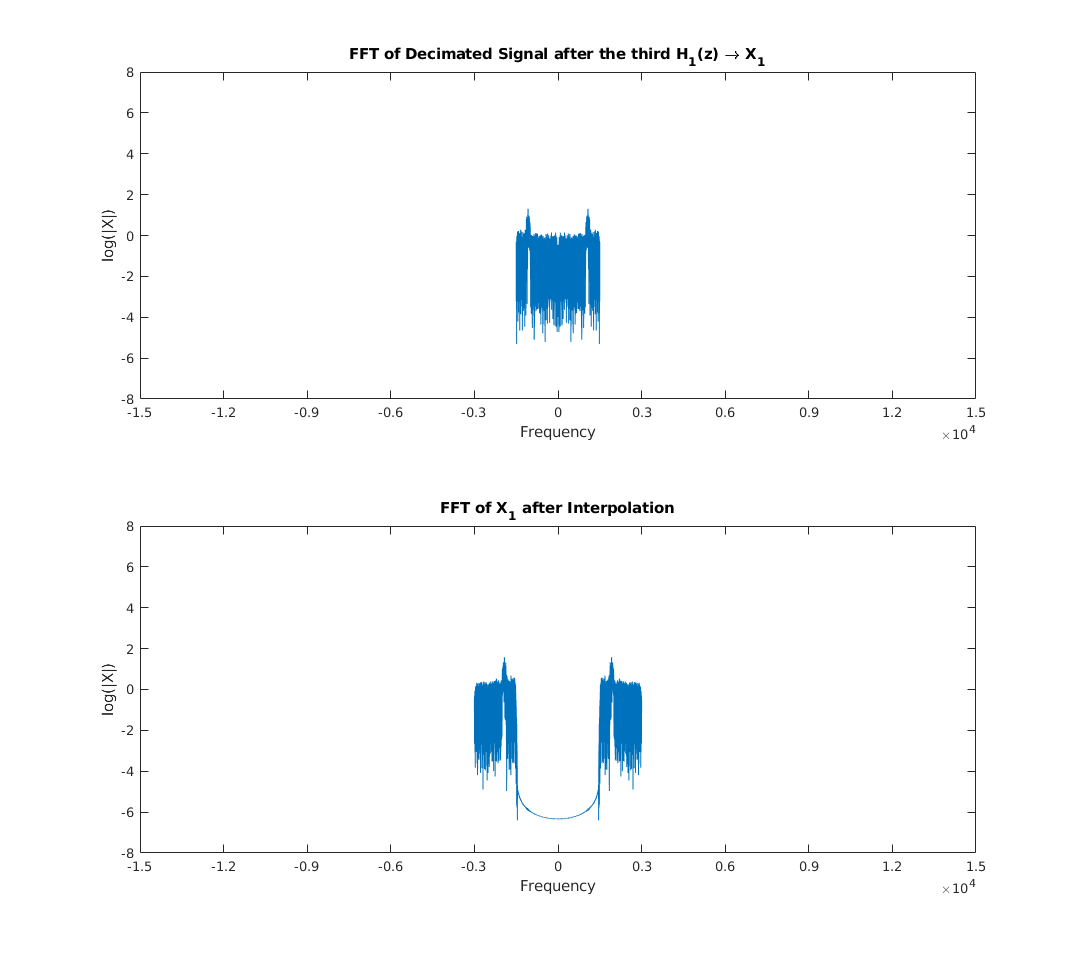

upsampledSigHP3 = [upsampledSigHP3 zeros(1, delay)];
interpolatedSigHP3 = filter(hHP, 1, upsampledSigHP3);

interpolatedSigHP3FFT = log(abs(fftshift(fft(interpolatedSigHP3))));     % Zero-Centered FFT
interpolatedSigHP3F = (-length(interpolatedSigHP3)/2:...
    length(interpolatedSigHP3)/2-1)/length(interpolatedSigHP3)...
    *Fs/8*L;                           % Zero-Centered Frequency Range 

graph = figure;
subplot(211)
plot(decimatedSigHP3F, decimatedSigHP3FFT)
title('FFT of Decimated Signal after the third H_1(z) \rightarrow X_1');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
subplot(2,1, 2)
plot(interpolatedSigHP3F, interpolatedSigHP3FFT)
title('FFT of X_1 after Interpolation');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.5]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
xlim([-15000 15000])
ylim([-8 8])

Now we do the same for the lower-bound of this signal which is $X_0$.

upsampledSigLP3(1:L:L*length(decimatedSigLP3)) = decimatedSigLP3;

Now we interpolate the upsampled signal with the same LowPass filter.

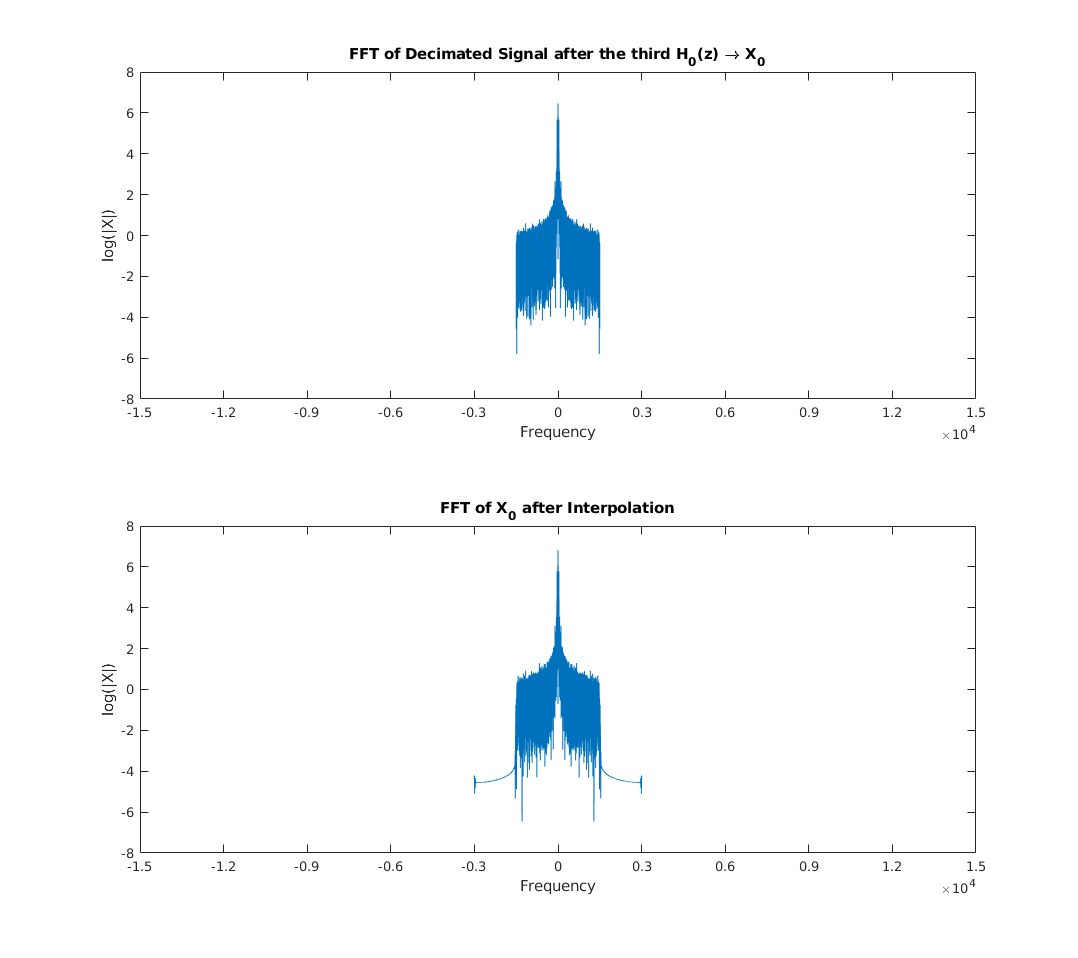

upsampledSigLP3 = [upsampledSigLP3 zeros(1, delay)];
interpolatedSigLP3 = filter(hLP, 1, upsampledSigLP3);

interpolatedSigLP3FFT = log(abs(fftshift(fft(interpolatedSigLP3))));     % Zero-Centered FFT
interpolatedSigLP3F = (-length(interpolatedSigLP3)/2:...
    length(interpolatedSigLP3)/2-1)/length(interpolatedSigLP3)...
    *Fs/8*L;                           % Zero-Centered Frequency Range 

graph = figure;
subplot(211)
plot(decimatedSigLP3F, decimatedSigLP3FFT)
title('FFT of Decimated Signal after the third H_0(z) \rightarrow X_0');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
subplot(2,1, 2)
plot(interpolatedSigLP3F, interpolatedSigLP3FFT)
title('FFT of X_0 after Interpolation');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.5]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
xlim([-15000 15000])
ylim([-8 8])

Now let's combine the upper-bound and lower-bound signal. And then we will compare the result to the original signal that $X_0$ and $X_1$ was derived from (that signal would be the input signal after Lowpass filtering and downsampling two times).

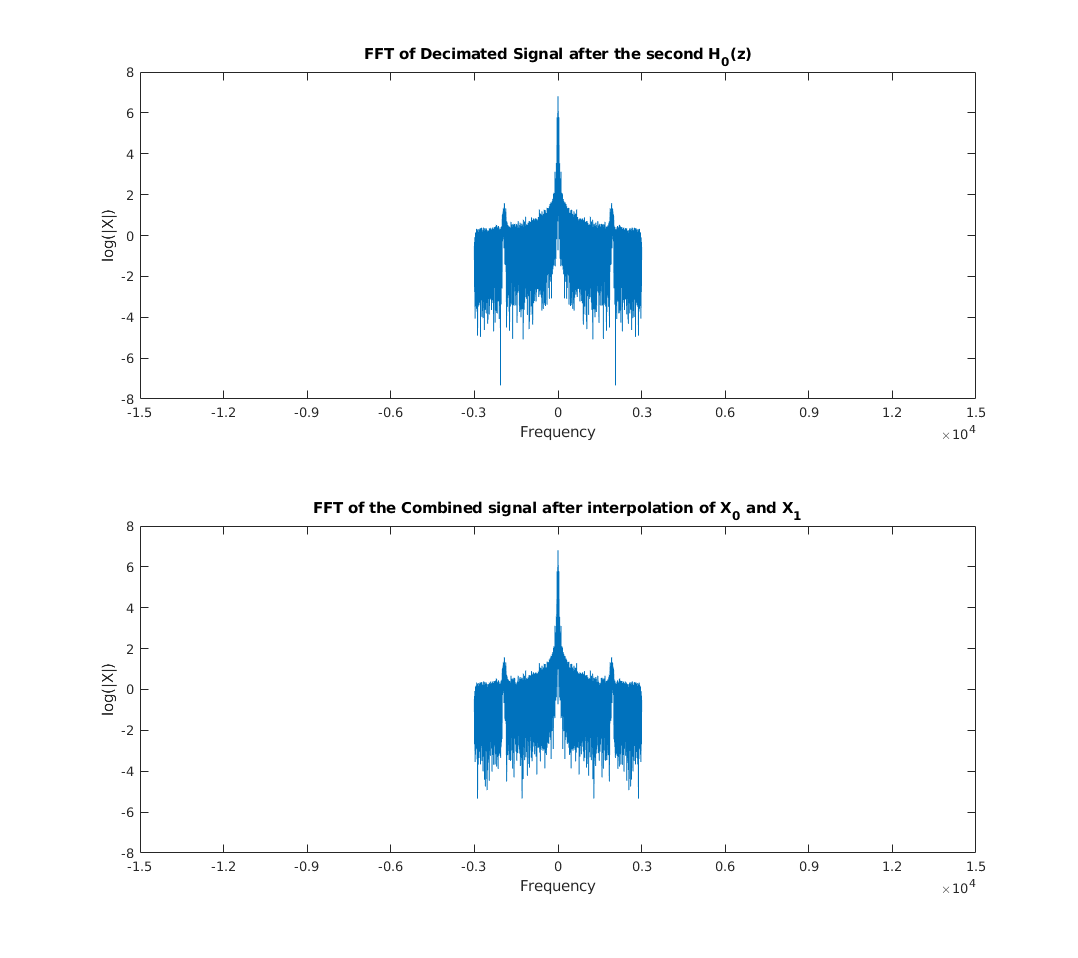

interpolatedSigCombined3 = interpolatedSigLP3 + interpolatedSigHP3;

interpolatedSigCombined3FFT = log(abs(fftshift(fft(interpolatedSigCombined3))));     % Zero-Centered FFT
interpolatedSigCombined3F = (-length(interpolatedSigCombined3)/2:...
    length(interpolatedSigCombined3)/2-1)/length(interpolatedSigCombined3)...
    *Fs/8*L;                           % Zero-Centered Frequency Range 

graph = figure;
subplot(211)
plot(decimatedSigLP2F, decimatedSigLP2FFT)
title('FFT of Decimated Signal after the second H_0(z)');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
subplot(2,1, 2)
plot(interpolatedSigCombined3F, interpolatedSigCombined3FFT)
title('FFT of the Combined signal after interpolation of X_0 and X_1');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.5]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
xlim([-15000 15000])
ylim([-8 8])

As you can see the signals look very similar in the frequency domain. However the value of the FFT is different from the original signal. Let's see what effect this has in the time-domain:

Let's compare them in the time-domain and make sure there are no distortions:

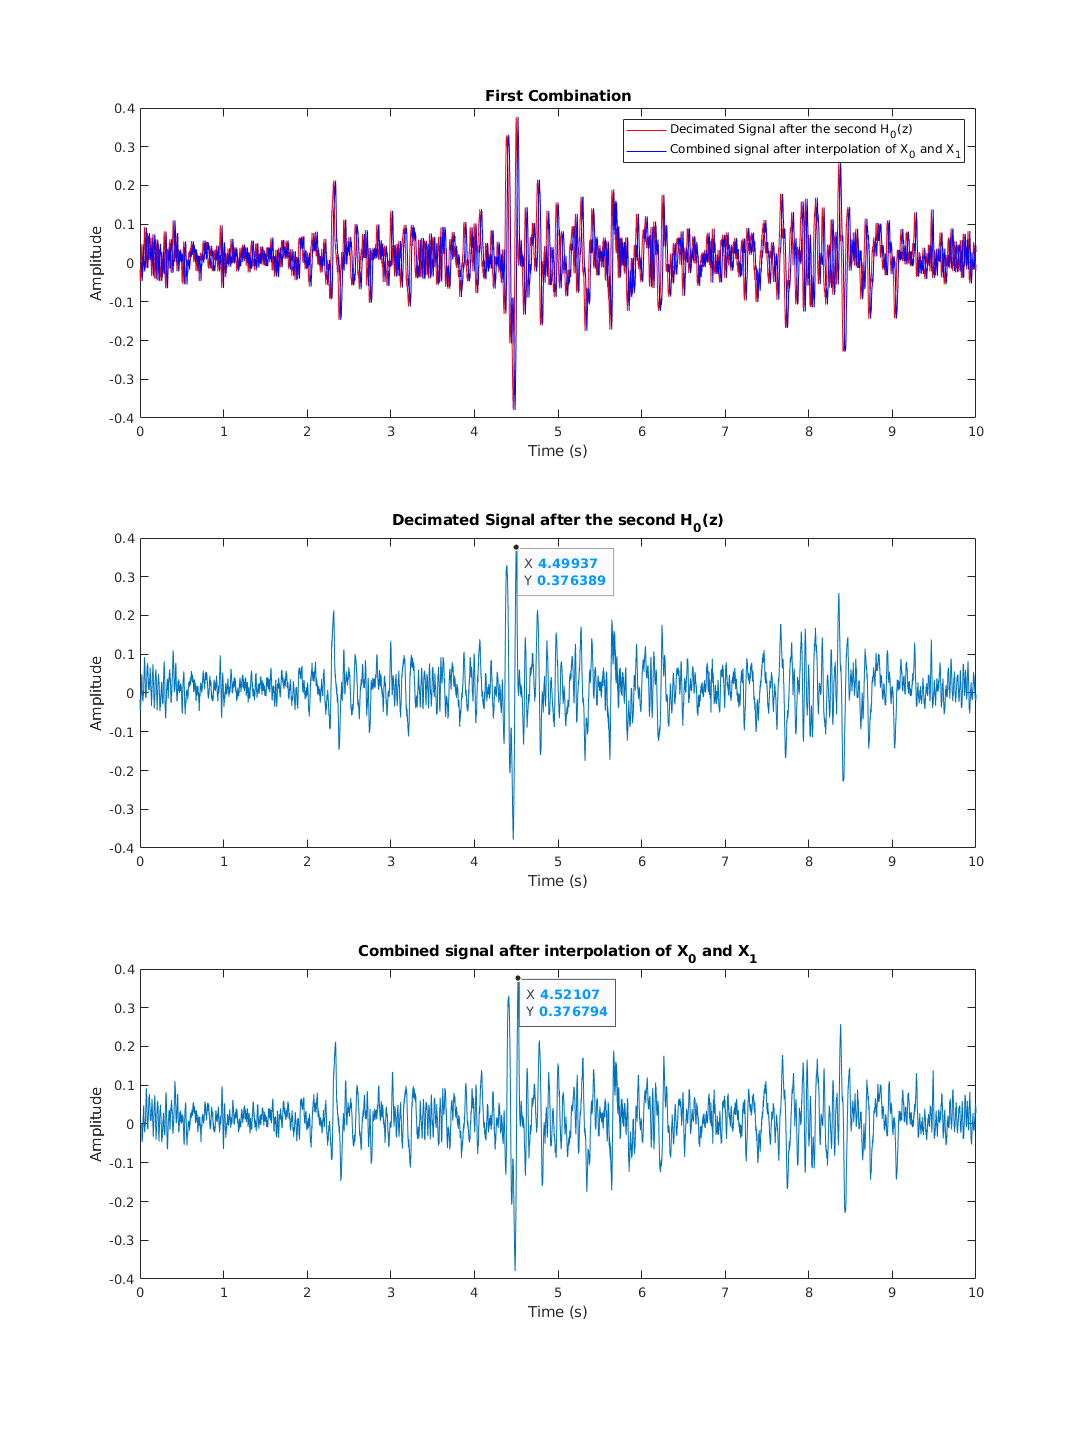

timeInterpolatedSigCombined3 = linspace(0, inputInfo.Duration, length(interpolatedSigCombined3));
timeDecimatedSigLP2 = linspace(0, inputInfo.Duration, length(decimatedSigLP2));

h = figure;
subplot(3,1,1)
plot(timeDecimatedSigLP2, decimatedSigLP2 , '-r')
hold on
plot(timeInterpolatedSigCombined3, interpolatedSigCombined3, '-b')
title('First Combination')
legend('Decimated Signal after the second H_0(z)','Combined signal after interpolation of X_0 and X_1')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
set(h,'Units','normalized','Position',[0 0 1 .25]);
hold off
subplot(312)
plot(timeDecimatedSigLP2, decimatedSigLP2)
title('Decimated Signal after the second H_0(z)')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
ax = gca;
chart = ax.Children(1);
datatip(chart,4.49937,0.376389);
subplot(313)
plot(timeInterpolatedSigCombined3, interpolatedSigCombined3)
title('Combined signal after interpolation of X_0 and X_1')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
ax = gca;
chart = ax.Children(1);
datatip(chart,4.52107,0.376794);
set(h,'Units','normalized','Position',[0 0 1 0.75]);

Looking at the figures above, we can conclude that time delay adjustment is working properly and there's very minimal time delay between the signals.

Let's continue with combining the signal until we get back to the input signal:

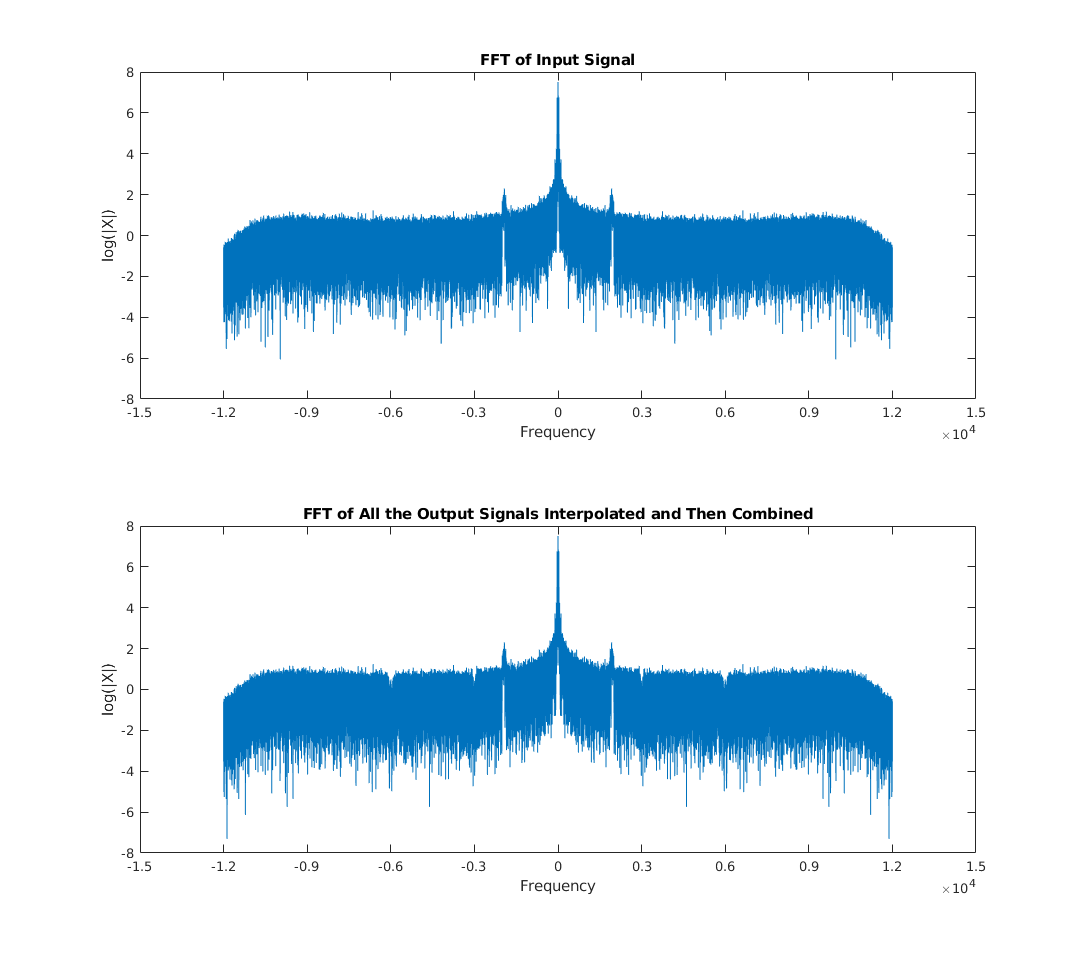

% Interpolating X2
upsampledSigHP2(1:L:L*length(decimatedSigHP2)) = decimatedSigHP2;
upsampledSigHP2 = [upsampledSigHP2 zeros(1, delay)];
interpolatedSigHP2 = filter(hHP, 1, upsampledSigHP2);

% Interpolating the last combined interpolated signal
upsampledSigCombined2(1:L:L*length(interpolatedSigCombined3)) = interpolatedSigCombined3;
upsampledSigCombined2 = [upsampledSigCombined2 zeros(1, delay)];
interpolatedSigLP2 = filter(hLP, 1, upsampledSigCombined2);

% Combining the two signals
interpolatedSigCombined2 = interpolatedSigHP2 + interpolatedSigLP2;

% Interpolating X3
upsampledSigHP1(1:L:L*length(decimatedSigHP1)) = decimatedSigHP1;
upsampledSigHP1 = [upsampledSigHP1 zeros(1, delay)];
interpolatedSigHP1 = filter(hHP, 1, upsampledSigHP1);

% Interpolating the last combined interpolated signal
upsampledSigCombined1(1:L:L*length(interpolatedSigCombined2)) = interpolatedSigCombined2;
upsampledSigCombined1 = [upsampledSigCombined1 zeros(1, delay+2)];
interpolatedSigLP1 = filter(hLP, 1, upsampledSigCombined1);

% Combining the two signals
interpolatedSigCombined1 = interpolatedSigHP1 + interpolatedSigLP1;

interpolatedSigCombined1FFT = log(abs(fftshift(fft(interpolatedSigCombined1))));     % Zero-Centered FFT
interpolatedSigCombined1F = (-length(interpolatedSigCombined1)/2:...
    length(interpolatedSigCombined1)/2-1)/length(interpolatedSigCombined1)...
    *Fs/2*L;                           % Zero-Centered Frequency Range 

graph = figure;
subplot(211)
plot(f0Input, inputFFT)
title('FFT of Input Signal');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
subplot(2,1, 2)
plot(interpolatedSigCombined1F, interpolatedSigCombined1FFT)
title('FFT of All the Output Signals Interpolated and Then Combined');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.5]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
xlim([-15000 15000])
ylim([-8 8])

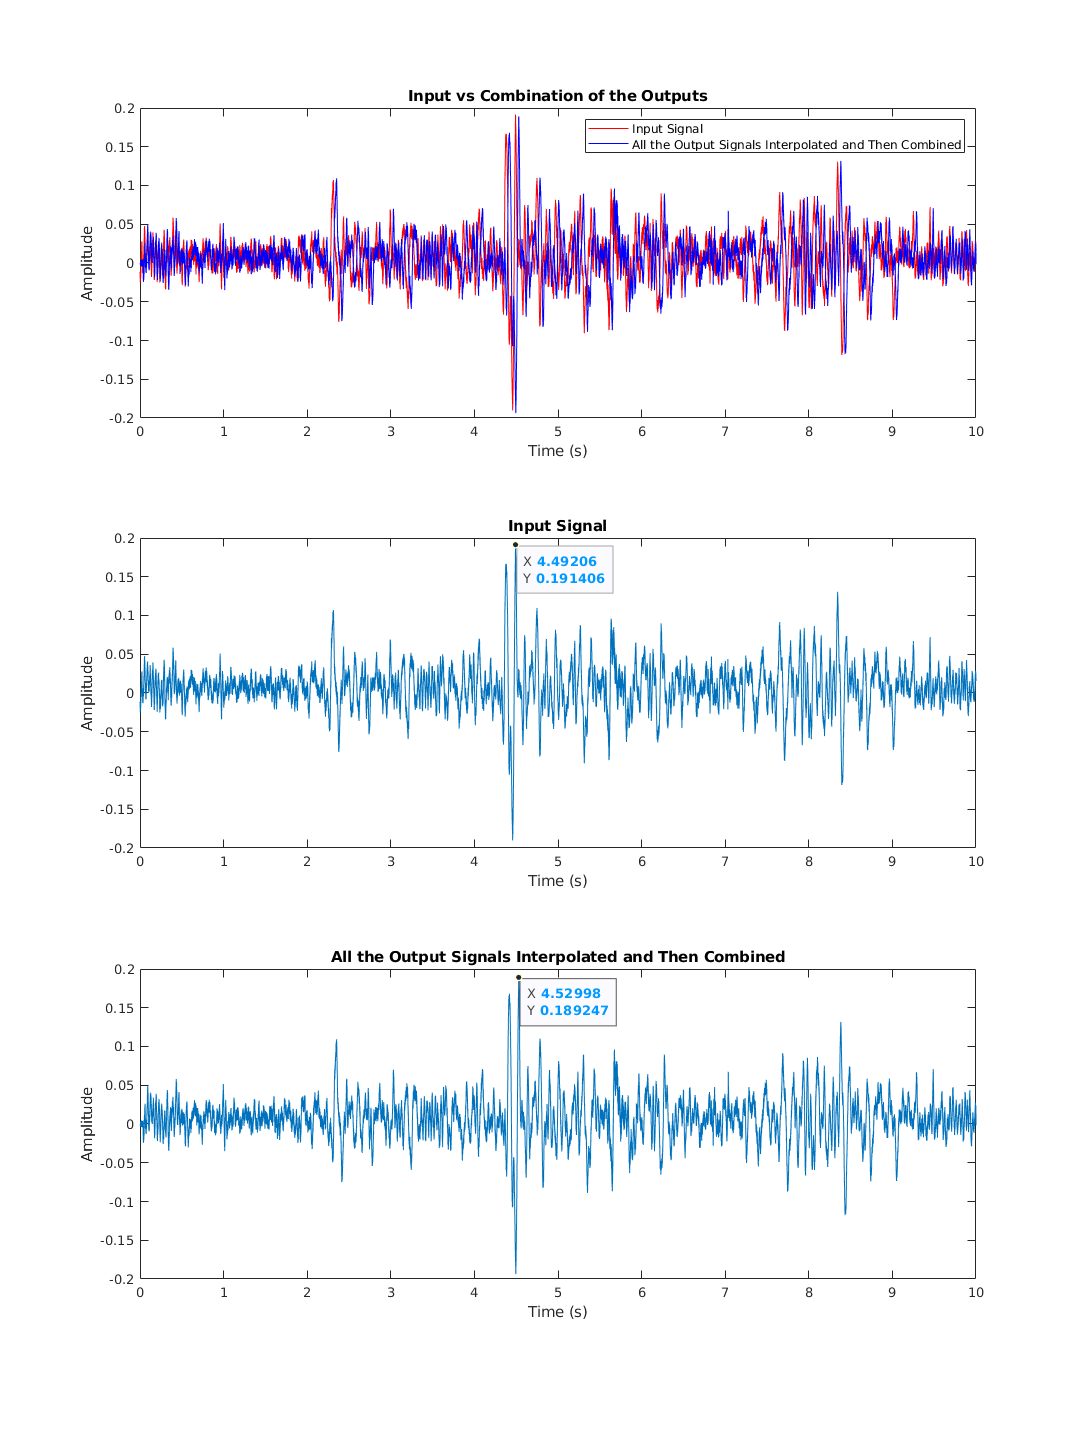

audiowrite('CombinedOutputSignals.wav',interpolatedSigCombined1, Fs)

timeInterpolatedSigCombined1 = linspace(0, inputInfo.Duration, length(interpolatedSigCombined1));

h = figure;
subplot(3,1,1)
plot(timeInput, inputSig , '-r')
hold on
plot(timeInterpolatedSigCombined1, interpolatedSigCombined1, '-b')
title('Input vs Combination of the Outputs')
legend('Input Signal','All the Output Signals Interpolated and Then Combined')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
set(h,'Units','normalized','Position',[0 0 1 .25]);
hold off
subplot(312)
plot(timeInput, inputSig)
title('Input Signal')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
ax = gca;
chart = ax.Children(1);
datatip(chart,4.49206,0.191406);
subplot(313)
plot(timeInterpolatedSigCombined1, interpolatedSigCombined1)
title('All the Output Signals Interpolated and Then Combined')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
ax = gca;
chart = ax.Children(1);
datatip(chart,4.52998,0.18924);
set(h,'Units','normalized','Position',[0 0 1 0.75]);

Looking at the combined outputs and comparing them to the original input signal we can see that there is in fact very minimal differences between the two. There's a small delay still between the two signals which as you can see in the figures is around 30ms. We concluded that this is not a signficant delay between the two signal and there are no major distortions either.

### Quantization

We are going to be trying out different approaches for quantization of our outputs and then compare them.

We will be comparing them based on their compression rate.

#### Approach 1:

The Input signal was 16 bits. We know that our quail call only exists in $X_1$; lets assign 16 bits to $X_1$ and look at the results.

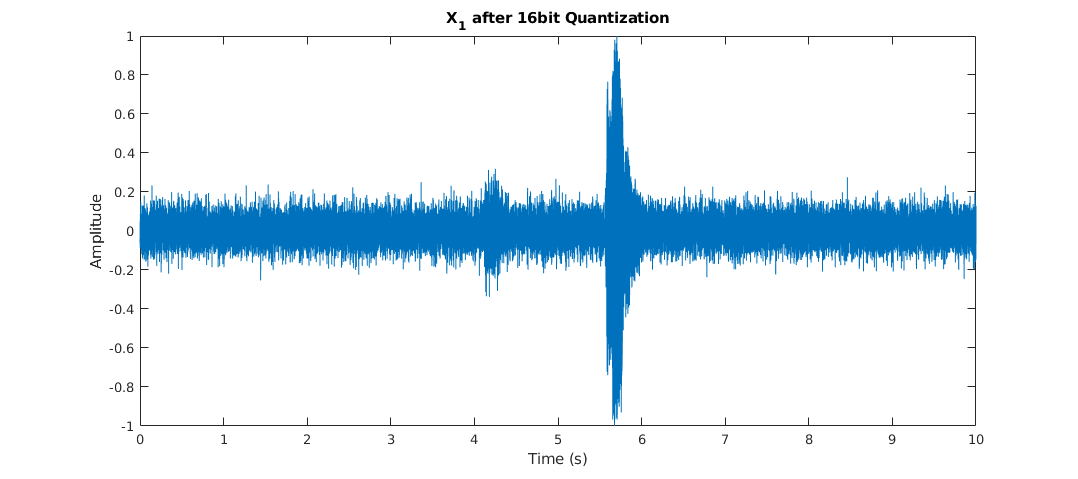

nbits = 16;
partition = -1+2/(2^nbits):2/(2^nbits):1;
codebook = -1:2/(2^nbits):1;

% We will quantize the rescaled/normalized version of X1
decimatedSigHP3_norm = rescale(decimatedSigHP3, -1, 1);
[~, X1_quantized_16] = quantiz(decimatedSigHP3_norm, partition, codebook);

audiowrite('X1_Quantized_16bit.wav', X1_quantized_16, Fs/8);

h = figure;
plot(timeDecimatedSigLP3, X1_quantized_16)
title('X_1 after 16bit Quantization')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
set(h,'Units','normalized','Position',[0 0 1 .25]);

As you can see, the results looks very similar to the original $X_1$. To quantify this measurement, lets use **Coefficient of Determination**, $R^2$**. **$R^2$ is one measure of comparing the data, and falls between 0 and 1. The higher the value of $R^2$, the closer the output signal is to the input. The reason we are using this measurement instead of other ones is because the values of our signal is extrememly small and the other comparison methods wouldn't do as good of a job as $R^2$ in showing the difference between the data. The following equation shows how $R^2$ is calculated:


$$ R^2 = 1 - \frac{\sum\limits_{i=1}^n \left(y_i - x_i\right)^2}{\sum\limits_{i=1}^n \left(y_i - \bar{y}\right)^2}.$$


Rsq = 1 - sum((decimatedSigHP3_norm - X1_quantized_16').^2)/...
    sum((decimatedSigHP3_norm - mean(decimatedSigHP3_norm)).^2)

Rsq = 1.0000

As we expected the result is equivalent to the original $X_1$ because the signal was originally quantized at 16 bits. Next, we will compare the size of this audio file to our original input signal.

source = dir("quailCall_middle.wav");
source_size = source.bytes

source_size = 480046

target = dir("X1_Quantized_16bit.wav");
target_size = target.bytes

target_size = 59818

compression_factor = source_size/target_size

compression_factor = 8.0251

You can see with using the 16 bit quantization, we are already compressing the input by a factor of 8.

#### Approach 2:

In the precvious approach we used the same quantization as the input signal for our $X_1$. Now lets do 8-bit quantization on $X_1$ and compare the results as before.

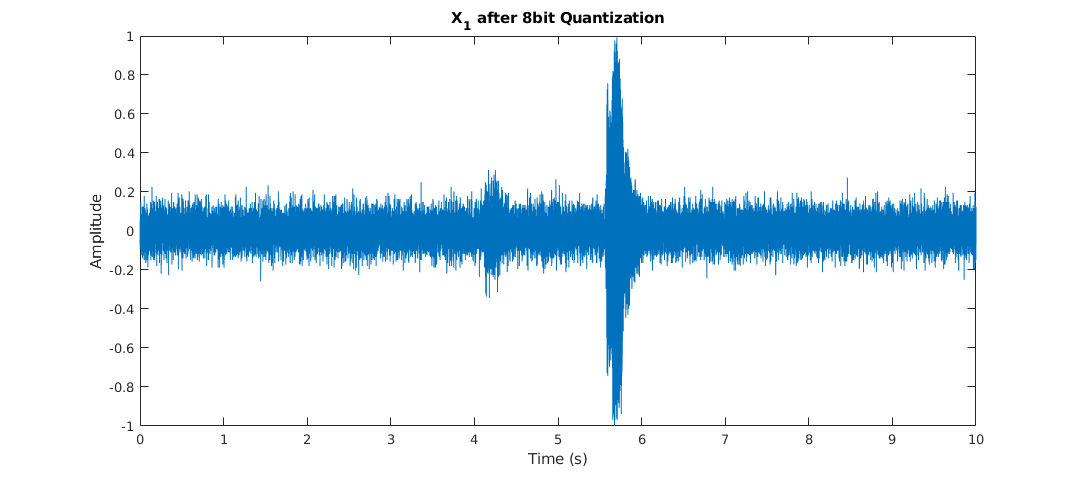

nbits = 8;
partition = -1+2/(2^nbits):2/(2^nbits):1;
codebook = -1:2/(2^nbits):1;

% We will quantize the rescaled/normalized version of X1
[~, X1_quantized_8] = quantiz(decimatedSigHP3_norm, partition, codebook);

audiowrite('X1_Quantized_8bit.wav', X1_quantized_8, Fs/8, 'BitsPerSample', 8);

h = figure;
plot(timeDecimatedSigLP3, X1_quantized_8)
title('X_1 after 8bit Quantization')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
set(h,'Units','normalized','Position',[0 0 1 .25]);

As you can see, the results still looks very similar to the original $X_1$. Let's compare them:

Rsq = 1 - sum((decimatedSigHP3_norm - X1_quantized_8').^2)/...
    sum((decimatedSigHP3_norm - mean(decimatedSigHP3_norm)).^2)

Rsq = 0.9981

You can see how the difference between the two is still very minimal.

target = dir("X1_Quantized_8bit.wav");
target_size = target.bytes

target_size = 29932

compression_fact = source_size/target_size

compression_fact = 16.0379

You can see with using the 8-bit quantization, we are able to compress the input by a factor of 16 while almost maintaining the same quality of $X_1$.

#### Approach 3:

Now Let's distribute the 16 bits between $X_1$ and $X_0$. We've already quantized $X_1$ at 8 bits. So we will quantize $X_0$.

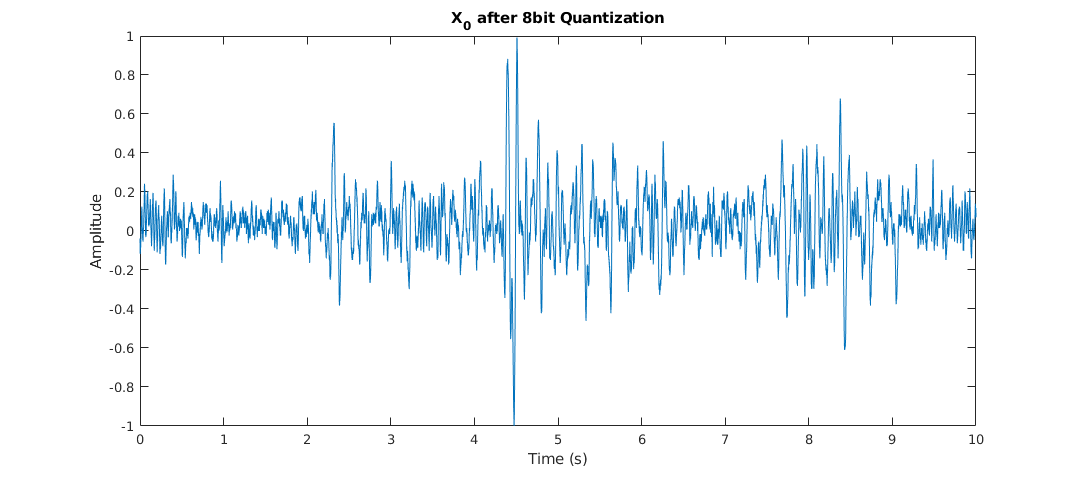

% We will quantize the rescaled/normalized version of X0
decimatedSigLP3_norm = rescale(decimatedSigLP3, -1, 1);
[~, X0_quantized_8] = quantiz(decimatedSigLP3_norm, partition, codebook);

audiowrite('X0_Quantized_8bit.wav', X0_quantized_8, Fs/8, 'BitsPerSample', 8);

h = figure;
plot(timeDecimatedSigLP3, X0_quantized_8)
title('X_0 after 8bit Quantization')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
set(h,'Units','normalized','Position',[0 0 1 .25]);

As you can see, the results still looks very similar to the original $X_0$. Let's compare them:

Rsq = 1 - sum((decimatedSigLP3_norm - X0_quantized_8').^2)/...
    sum((decimatedSigLP3_norm - mean(decimatedSigLP3_norm)).^2)

Rsq = 0.9992

You can see how the difference between the two is still very minimal.

Now to find the compression factor for this approach, we are going to add the file sizes of both $X_0$ and $X_1$ quantized at 8-bits.

target1 = dir("X0_Quantized_8bit.wav");
target2 = dir("X1_Quantized_8bit.wav");
target_size1 = target1.bytes

target_size1 = 29932

target_size2 = target2.bytes

target_size2 = 29932

compression_fact = source_size/(target_size1 + target_size2)

compression_fact = 8.0189

You can see with distributing the 16 bits between $X_0$ and $X_1$, we are now compressing the input file by a factor of 8.

From the two approaches before, we learned that an 8-bit quantization of the outputs would still maintain the same quality of the original signals (16-bit).

#### Approach 4:

Now Let's Assign 8-bits to each sub-band, $X_0$, $X_1$, and $X_2$. 

*Note: Unfortunately due to MATLAB's limited capabilities, we cannot assign less than 8-bits to these signals and then write them to disk.*

% We will quantize the rescaled/normalized version of X2
decimatedSigHP2_norm = rescale(decimatedSigHP2, -1, 1);
[~, X2_quantized_8] = quantiz(decimatedSigHP2_norm, partition, codebook);

audiowrite('X2_Quantized_8bit.wav', X2_quantized_8, Fs/4, 'BitsPerSample', 8);

Let's caluclate the compression factor now:

target3 = dir("X2_Quantized_8bit.wav");
target_size3 = target3.bytes

target_size3 = 59948

compression_fact = source_size/(target_size1 + target_size2 + target_size3)

compression_fact = 4.0067

You can see by assigning 8-bits to the three sub-bands, , we are now compressing the input file by a factor of 4.

#### Approach 5:

Now Let's Assign 8-bits to each sub-band, $X_0$, $X_1$, $X_2$, and $X_3$. 

% We will quantize the rescaled/normalized version of X3
decimatedSigHP1_norm = rescale(decimatedSigHP1, -1, 1);
[~, X3_quantized_8] = quantiz(decimatedSigHP1_norm, partition, codebook);

audiowrite('X3_Quantized_8bit.wav', X3_quantized_8, Fs/2, 'BitsPerSample', 8);

Let's calculate the compression factor now:

target4 = dir("X3_Quantized_8bit.wav");
target_size4 = target4.bytes

target_size4 = 119980

compression_fact = source_size/(target_size1 + target_size2 + target_size3 + target_size4)

compression_fact = 2.0019

You can see with assigning 8-bits to each sub-band, , we are now compressing the input file by only a factor of 3.

For this project, we are going to use the data from Approaches 2, 3, and 5 for decoding and compare the results.

## The Decoder

The decoder will take the compressed binary file as an input and will reconstruct the signal at its original sampling rate. We are going to start approach 5 where we have all 4 bands each with 8-bits assigned to them.

#### Using quantized data from Approach 5

Let's read the 4 bands;

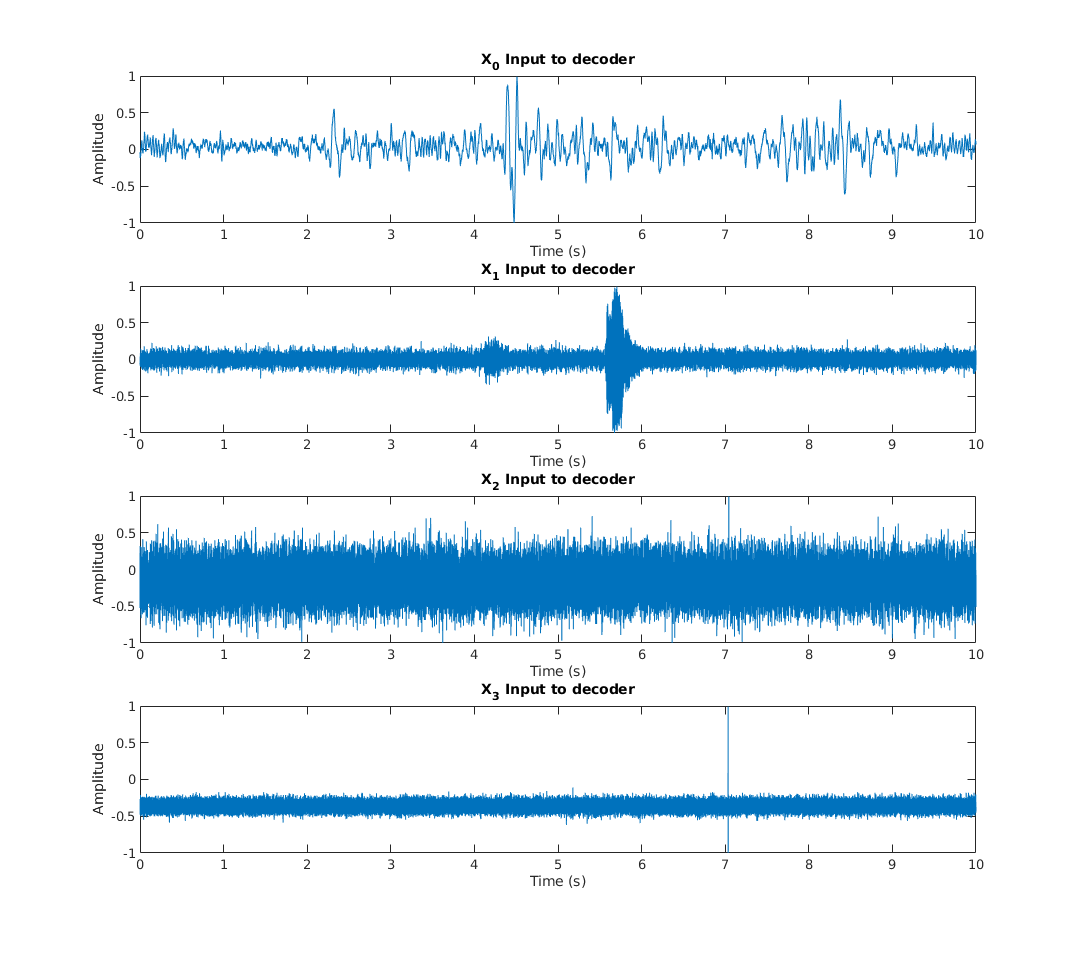

delay_decoder = 905;

[X0_Input, Fs0] = audioread("X0_Quantized_8bit.wav");
[X1_Input, Fs1] = audioread("X1_Quantized_8bit.wav");
[X2_Input, Fs2] = audioread("X2_Quantized_8bit.wav");
[X3_Input, Fs3] = audioread("X3_Quantized_8bit.wav");

X0_inputTime = linspace(0, inputInfo.Duration, length(X0_Input));
X1_inputTime = linspace(0, inputInfo.Duration, length(X1_Input));
X2_inputTime = linspace(0, inputInfo.Duration, length(X2_Input));
X3_inputTime = linspace(0, inputInfo.Duration, length(X3_Input));

h = figure;
subplot(4,1,1)
plot(X0_inputTime, X0_Input)
title('X_0 Input to decoder')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
subplot(412)
plot(X1_inputTime, X1_Input)
title('X_1 Input to decoder')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
subplot(413)
plot(X2_inputTime, X2_Input)
title('X_2 Input to decoder')
ylabel('Amplitude') 
xlabel('Time (s)')
xlim([0 10])
subplot(414)
plot(X3_inputTime, X3_Input)
title('X_3 Input to decoder')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
set(h,'Units','normalized','Position',[0 0 1 0.5]);

First we will unpack the bits for each sample and then scale them back to their original scale.

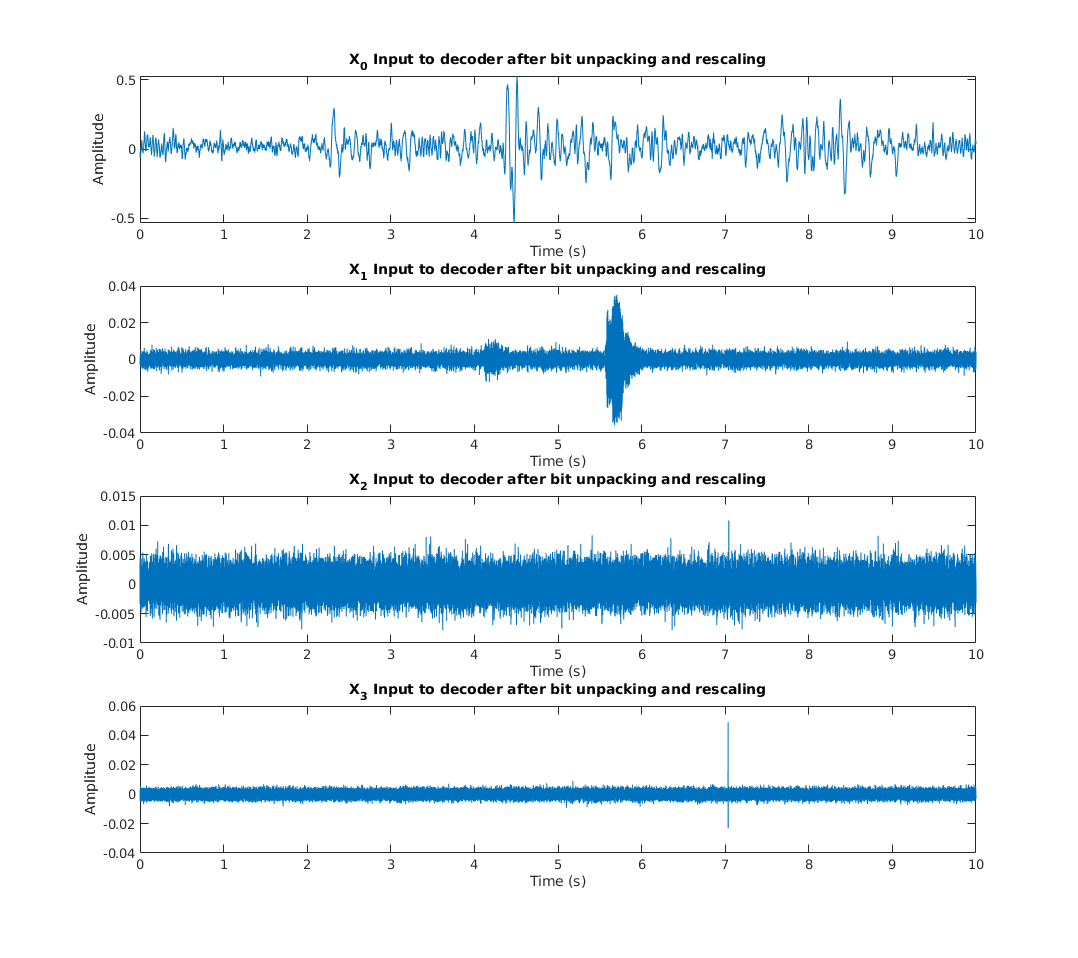

nbits = 16;
partition = -1+2/(2^nbits):2/(2^nbits):1;
codebook = -1:2/(2^nbits):1;

% Unpacking the bits
[~, X0_Input_unpacked] = quantiz(X0_Input, partition, codebook);
[~, X1_Input_unpacked] = quantiz(X1_Input, partition, codebook);
[~, X2_Input_unpacked] = quantiz(X2_Input, partition, codebook);
[~, X3_Input_unpacked] = quantiz(X3_Input, partition, codebook);

% Rescaling to original scale first
X0 = rescale(X0_Input_unpacked, min(decimatedSigLP3), max(decimatedSigLP3));
X1 = rescale(X1_Input_unpacked, min(decimatedSigHP3), max(decimatedSigHP3));
X2 = rescale(X2_Input_unpacked, min(decimatedSigHP2), max(decimatedSigHP2));
X3 = rescale(X3_Input_unpacked, min(decimatedSigHP1), max(decimatedSigHP1));

% Lets visualize them again

h = figure;
subplot(4,1,1)
plot(X0_inputTime, X0)
title('X_0 Input to decoder after bit unpacking and rescaling')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
subplot(412)
plot(X1_inputTime, X1)
title('X_1 Input to decoder after bit unpacking and rescaling')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
subplot(413)
plot(X2_inputTime, X2)
title('X_2 Input to decoder after bit unpacking and rescaling')
ylabel('Amplitude') 
xlabel('Time (s)')
xlim([0 10])
subplot(414)
plot(X3_inputTime, X3)
title('X_3 Input to decoder after bit unpacking and rescaling')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
set(h,'Units','normalized','Position',[0 0 1 0.5]);

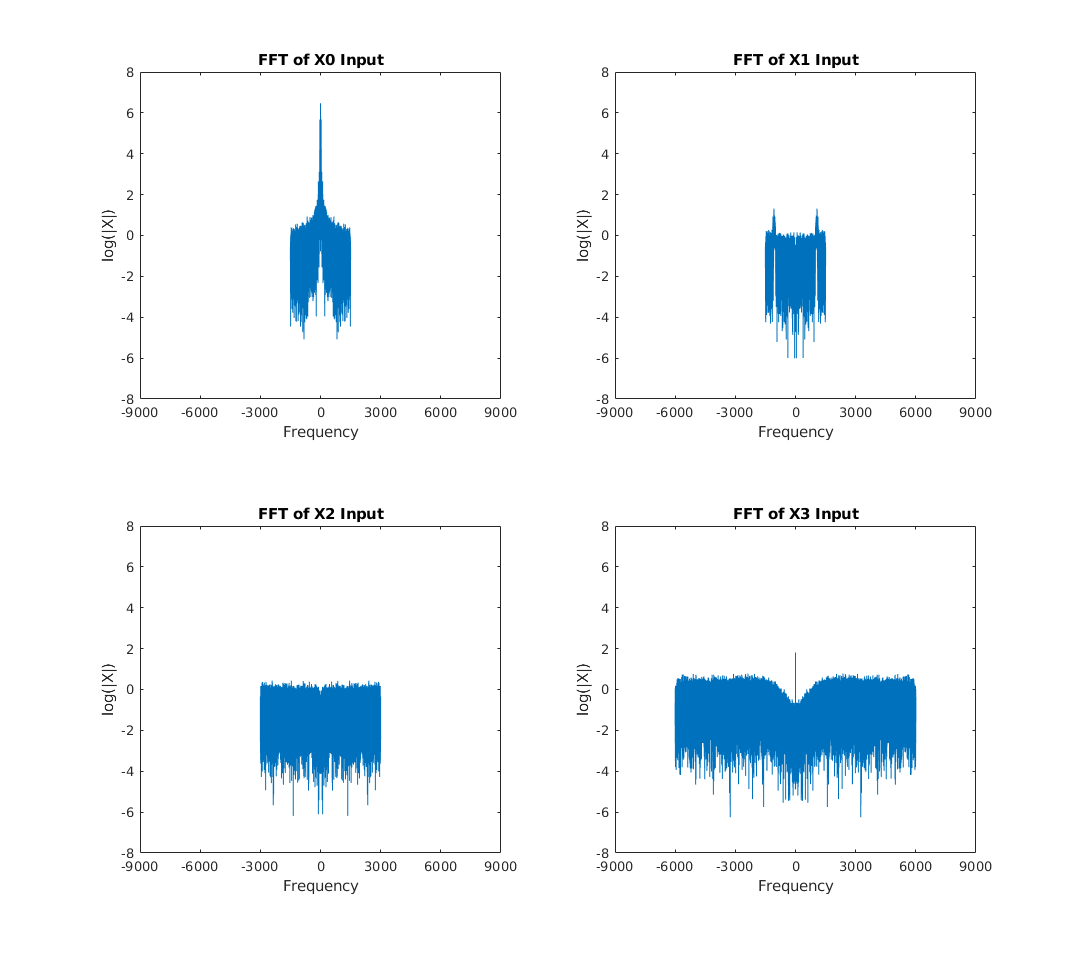

X0FFT = log(abs(fftshift(fft(X0))));                       % Zero-Centered FFT  
X0F = (-length(X0)/2: length(X0)/2-1)/length(X0)*Fs0;      % Zero-Centered Frequency Range 
X1FFT = log(abs(fftshift(fft(X1))));                       % Zero-Centered FFT  
X1F = (-length(X1)/2: length(X1)/2-1)/length(X1)*Fs1;      % Zero-Centered Frequency Range 
X2FFT = log(abs(fftshift(fft(X2))));                       % Zero-Centered FFT  
X2F = (-length(X2)/2: length(X2)/2-1)/length(X2)*Fs2;      % Zero-Centered Frequency Range 
X3FFT = log(abs(fftshift(fft(X3))));                       % Zero-Centered FFT  
X3F = (-length(X3)/2: length(X3)/2-1)/length(X3)*Fs3;      % Zero-Centered Frequency Range 

    
graph = figure;
subplot(221)
plot(X0F, X0FFT)
title('FFT of X0 Input');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-9000 9000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -9000:3000:9000)
subplot(2,2, 2)                                                     
plot(X1F, X1FFT)
title('FFT of X1 Input');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-9000 9000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -9000:3000:9000)
subplot(223)
plot(X2F, X2FFT)
title('FFT of X2 Input');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-9000 9000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -9000:3000:9000)
subplot(224)
plot(X3F, X3FFT)
title('FFT of X3 Input');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-9000 9000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -9000:3000:9000)
set(graph,'Units','normalized','Position',[0 0 1 0.5]);

Now we need to do a similar process to what we did in the evaluation of our **Encoder **to combine the four bonds until we get one signal with the sampling rate as our input to the Encoder.

**Step 1: **First we upsample and interpolate our $X_0$ and $X_1$ and then combine them.

%% Lower-Band Signal
% Interpolating X0
upsampledX0(1:L:L*length(X0)) = X0;
upsampledX0 = [upsampledX0 zeros(1, delay)];
interpolatedX0 = filter(hLP, 1, upsampledX0);

%% Upper-Band Signal
% Interpolating X1
upsampledX1(1:L:L*length(X1)) = X1;
upsampledX1 = [upsampledX1 zeros(1, delay)];
interpolatedX1 = filter(hHP, 1, upsampledX1);

% Combining the X0 and X1
X0X1 = interpolatedX0 + interpolatedX1;

**Step 2: **Then we upsample and interpolate our ($X_0 +$$X_1$) and $X_2$ and then combine them again.

%% Lower-Band Signal
% Interpolating (X0 + X1)
upsampledX0X1(1:L:L*length(X0X1)) = X0X1;
upsampledX0X1 = [upsampledX0X1 zeros(1, delay)];
interpolatedX0X1 = filter(hLP, 1, upsampledX0X1);

%% Upper-Band Signal
% Interpolating X2
upsampledX2(1:L:L*length(X2)) = X2;
upsampledX2 = [upsampledX2 zeros(1, delay)];
interpolatedX2 = filter(hHP, 1, upsampledX2);

% Combining the (X0 + X1) and X2
X0X1X2 = interpolatedX0X1 + interpolatedX2;

**Step 3: **Finally we upsample and interpolate our ($X_0 +$$X_1 +X_2$) and $X_3$ and then combine them again.

%% Lower-Band Signal
% Interpolating (X0 + X1 + X2)
upsampledX0X1X2(1:L:L*length(X0X1X2)) = X0X1X2;
upsampledX0X1X2 = [upsampledX0X1X2 zeros(1, delay+2)];
interpolatedX0X1X2 = filter(hLP, 1, upsampledX0X1X2);

%% Upper-Band Signal
% Interpolating X3
upsampledX3(1:L:L*length(X3)) = X3;
upsampledX3 = [upsampledX3 zeros(1, delay)];
interpolatedX3 = filter(hHP, 1, upsampledX3);

% Combining the (X0 + X1 + X2) and X3
finalOutput = interpolatedX0X1X2 + interpolatedX3;

% Adjusting for delay
inputSig_wDelay_Decoder = inputSig(1:end-delay_decoder);
timeInput_wDelay_Decoder = timeInput(1:end-delay_decoder);
finalOutput_wDelay = finalOutput;
finalOutput_wDelay(1:delay_decoder) = [];

Let's Visualize the results and compare to our original input to the Encoder in the Frequency domain and Time Domain.

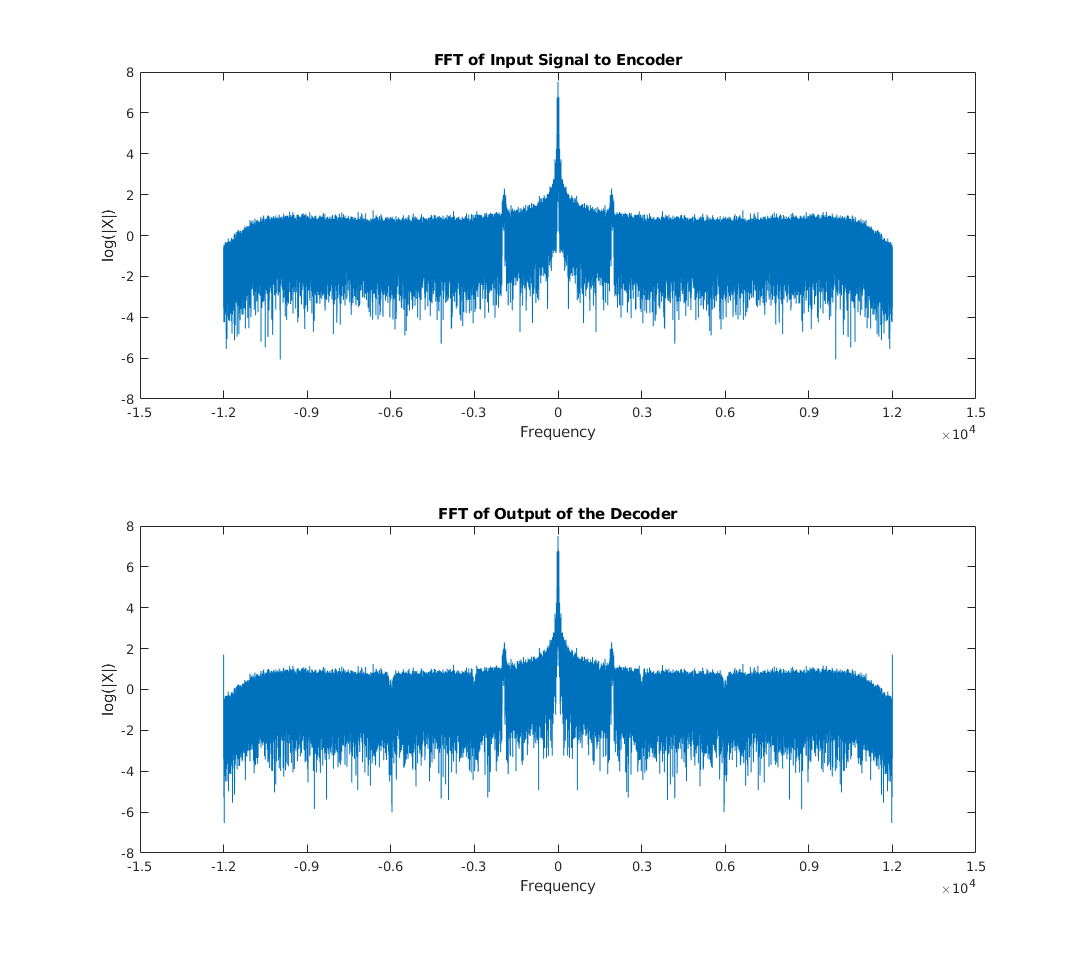

finalOutputFFT = log(abs(fftshift(fft(finalOutput))));                % Zero-Centered FFT  
finalOutputF = (-length(finalOutput)/2: length(finalOutput)/2-1)...
    /length(finalOutput)*Fs3*L;                                       % Zero-Centered Frequency Range 

graph = figure;
subplot(211)
plot(f0Input, inputFFT)
title('FFT of Input Signal to Encoder');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
subplot(2,1, 2)
plot(finalOutputF, finalOutputFFT)
title('FFT of Output of the Decoder');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.5]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
xlim([-15000 15000])
ylim([-8 8])

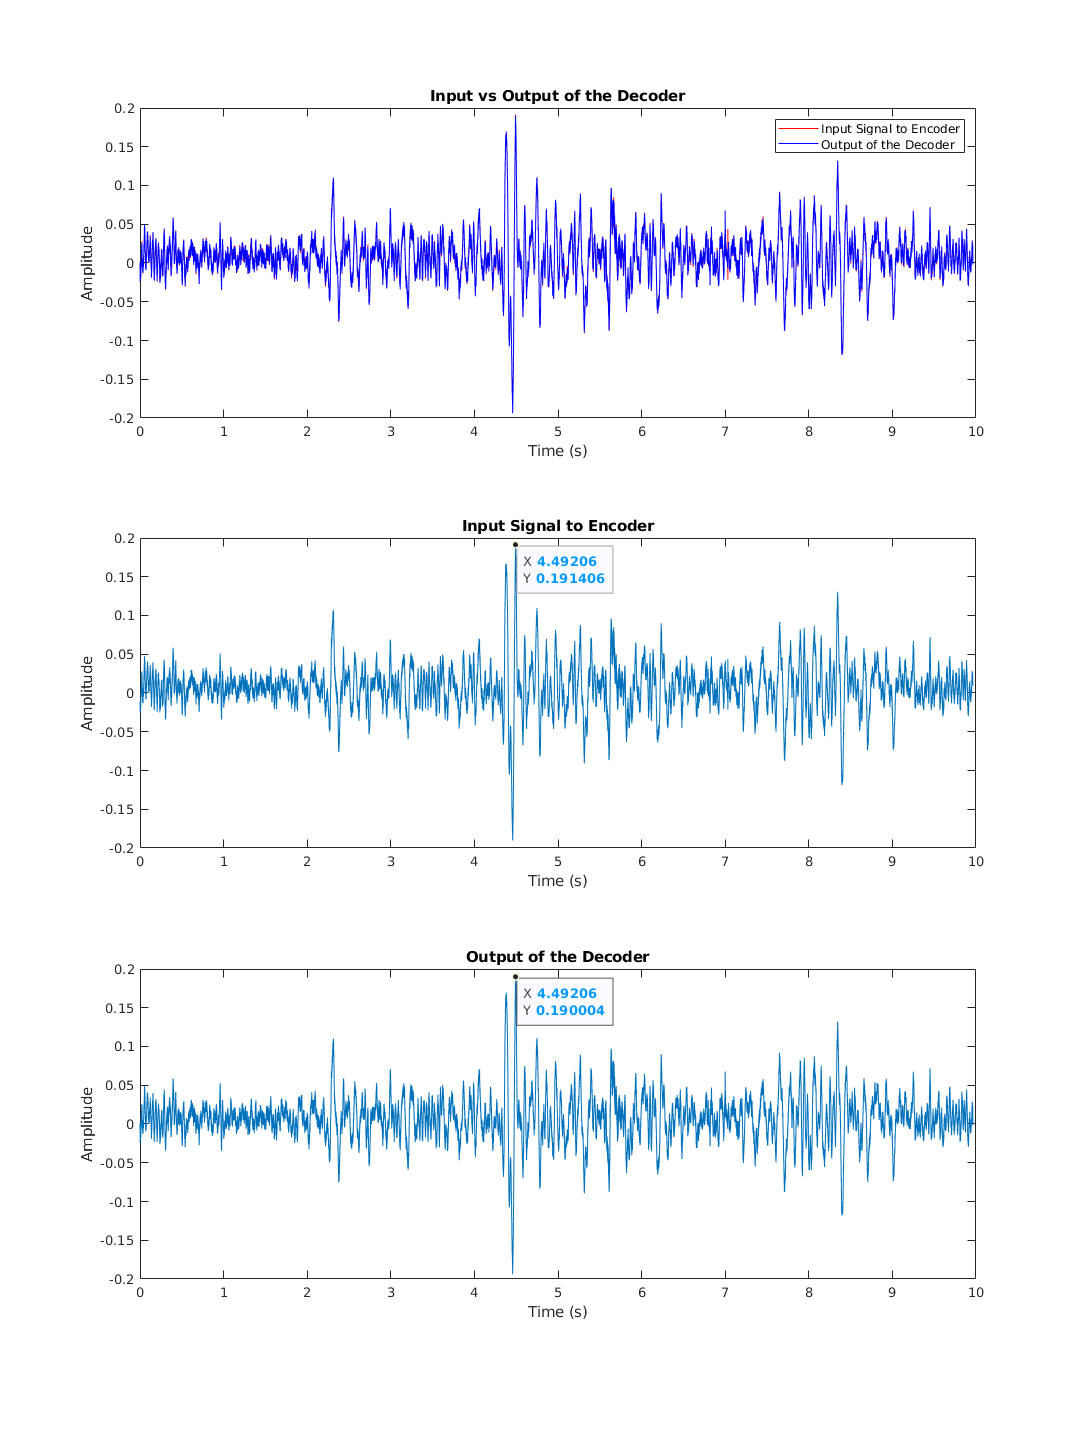

timefinalOutput_wDelay = linspace(0, timeInput_wDelay_Decoder(end), length(finalOutput_wDelay));

h = figure;
subplot(3,1,1)
plot(timeInput_wDelay_Decoder, inputSig_wDelay_Decoder , '-r')
hold on
plot(timefinalOutput_wDelay, finalOutput_wDelay, '-b')
title('Input vs Output of the Decoder')
legend('Input Signal to Encoder','Output of the Decoder')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
set(h,'Units','normalized','Position',[0 0 1 .25]);
hold off
subplot(312)
plot(timeInput_wDelay_Decoder, inputSig_wDelay_Decoder)
title('Input Signal to Encoder')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
ax = gca;
chart = ax.Children(1);
datatip(chart,4.49206,0.191406);
subplot(313)
plot(timefinalOutput_wDelay, finalOutput_wDelay)
title('Output of the Decoder')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
ax = gca;
chart = ax.Children(1);
datatip(chart,4.49206,0.19004);
set(h,'Units','normalized','Position',[0 0 1 0.75]);

You can see that using the data from **Approach 5**'s Quantizations we are able to recreate the Input Signal to our Encoder System using our designed Decoder System.

### The Quality Estimator

To estimate the Quality of Decoding System we are going to use both the $R^2$ measurement as before and the **Mean-Absolute Error.**

Note: For $R^2$, the closer the value to 1 the better and for $\textrm{MAE}$, the closer the value to 0 the better!

Let's measure the quality of the results from the previous section with **Appraoch 5 **data:

% R^2 Measurement
Rsq = 1 - sum((inputSig_wDelay_Decoder - finalOutput_wDelay').^2)...
    /sum((inputSig_wDelay_Decoder - mean(inputSig_wDelay_Decoder)).^2)

Rsq = 0.9843

% Mean-Absolute Error
mae(inputSig_wDelay_Decoder, finalOutput_wDelay')

ans = 0.0027

The results above show us that there is very minimal between the input to our Encoder system and the output of our Decoder system using the Apprach 5 Quantization Method.

#### Using quantized data from Approach 3

In the previous sections we showed that we could recreate the Input Signal to the Encoder using Data from **Approach 5 **Quantization method which was assigning 8bits to each 4 of the bonds. Using this method we were able to recreate the signal in very high quality. However the downfall to that method is that we are only getting a compression factor of 3.

Now we are going repeat the same process of Decoding with the **Approach 3 **data which is only assigning 8bits to $X_0$and $X_1$.

**Step 1: **First we upsample and interpolate our $X_0$ and $X_1$ and then combine them.

%% Lower-Band Signal
% Interpolating X0
upsampledX0_2(1:L:L*length(X0)) = X0;
upsampledX0_2 = [upsampledX0_2 zeros(1, delay)];
interpolatedX0_2 = filter(hLP, 1, upsampledX0_2);

%% Upper-Band Signal
% Interpolating X1
upsampledX1_2(1:L:L*length(X1)) = X1;
upsampledX1_2 = [upsampledX1_2 zeros(1, delay)];
interpolatedX1_2 = filter(hHP, 1, upsampledX1_2);

% Combining the X0 and X1
X0X1_2 = interpolatedX0_2 + interpolatedX1_2;

**Step 2: **Since we assigned 0 bits to $X_2$ we only need to upsample and interpolate ($X_0 +$$X_1$). 

%% Lower-Band Signal
% Interpolating (X0 + X1)
upsampledX0X1_2(1:L:L*length(X0X1_2)) = X0X1_2;
upsampledX0X1_2 = [upsampledX0X1_2 zeros(1, delay)];
interpolatedX0X1_2 = filter(hLP, 1, upsampledX0X1_2);

**Step 3: **Finally since we also assigned 0 bits to $X_3$ we only need to upsample and interpolate ($X_0 +$$X_1$)  again. 

%% Lower-Band Signal
% Interpolating (X0 + X1 + X2)
upsampledX0X1_3(1:L:L*length(interpolatedX0X1_2)) = interpolatedX0X1_2;
upsampledX0X1_3 = [upsampledX0X1_3 zeros(1, delay+2)];
finalOutput_2 = filter(hLP, 1, upsampledX0X1_3);
    
% Adjusting for delay
finalOutput_2_wDelay = finalOutput_2;
finalOutput_2_wDelay(1:delay_decoder) = [];

Let's Visualize the results and compare to our original input to the Encoder in the Frequency domain and Time Domain.

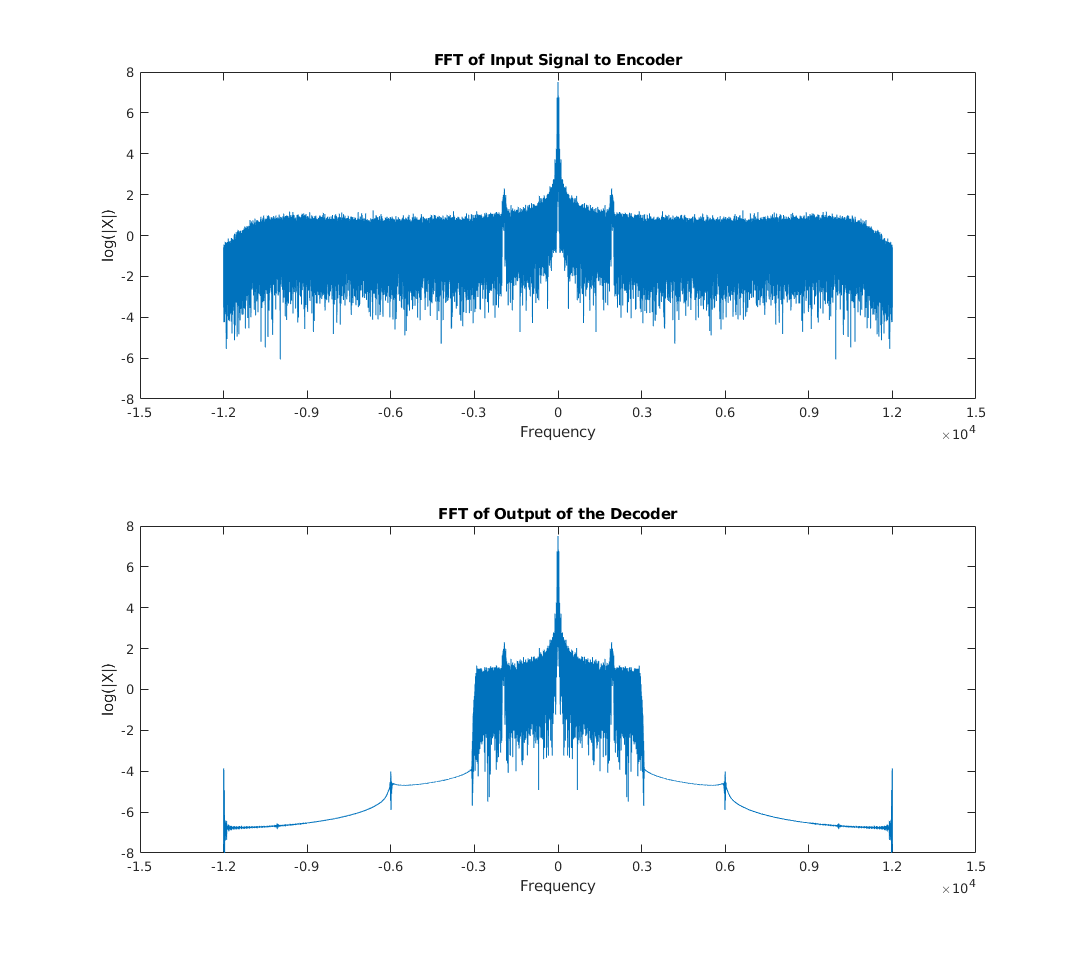

finalOutput_2FFT = log(abs(fftshift(fft(finalOutput_2))));                % Zero-Centered FFT  
finalOutput_2F = (-length(finalOutput_2)/2: length(finalOutput_2)/2-1)...
    /length(finalOutput_2)*Fs3*L;                                       % Zero-Centered Frequency Range 

graph = figure;
subplot(211)
plot(f0Input, inputFFT)
title('FFT of Input Signal to Encoder');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
subplot(2,1, 2)
plot(finalOutput_2F, finalOutput_2FFT)
title('FFT of Output of the Decoder');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.5]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
xlim([-15000 15000])
ylim([-8 8])

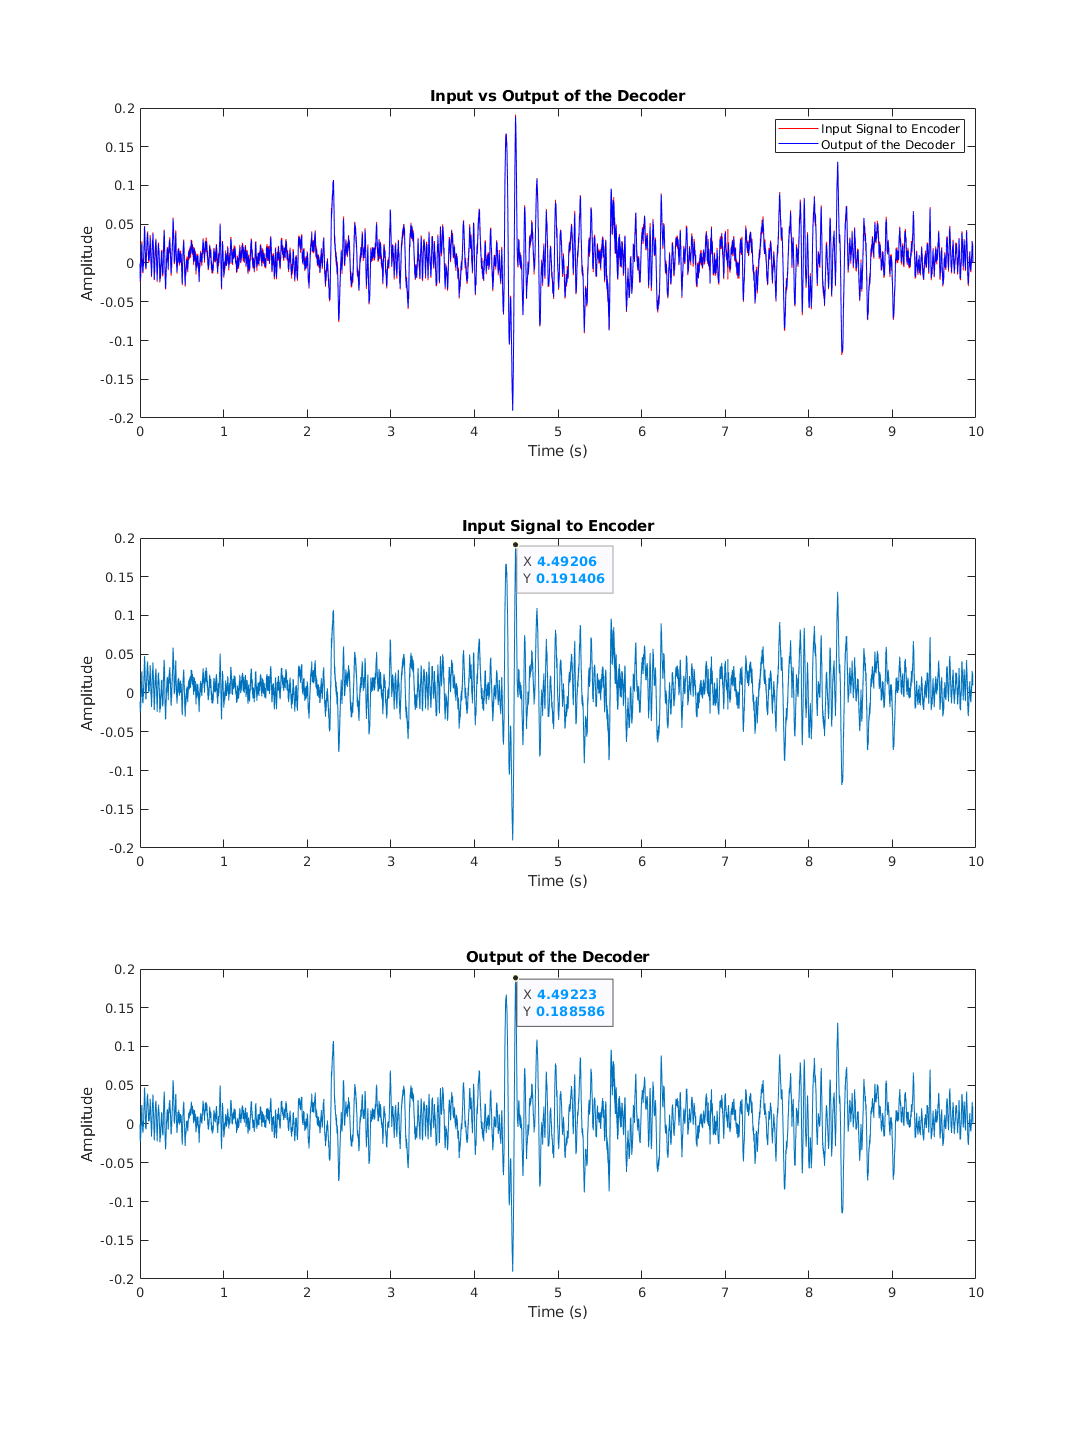

h = figure;
subplot(3,1,1)
plot(timeInput_wDelay_Decoder, inputSig_wDelay_Decoder , '-r')
hold on
plot(timefinalOutput_wDelay, finalOutput_2_wDelay, '-b')
title('Input vs Output of the Decoder')
legend('Input Signal to Encoder','Output of the Decoder')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
set(h,'Units','normalized','Position',[0 0 1 .25]);
hold off
subplot(312)
plot(timeInput_wDelay_Decoder, inputSig_wDelay_Decoder)
title('Input Signal to Encoder')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
ax = gca;
chart = ax.Children(1);
datatip(chart,4.49206,0.191406);
subplot(313)
plot(timefinalOutput_wDelay, finalOutput_2_wDelay)
title('Output of the Decoder')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
ax = gca;
chart = ax.Children(1);
datatip(chart,4.49206,0.19004);
set(h,'Units','normalized','Position',[0 0 1 0.75]);

Already just based on visual inspection you can see that the results are no different from **Approach 5 **Qunatization.

### The Quality Estimator

Let's measure the quality of the results from the previous section with **Appraoch 3 **data:

% R^2 Measurement
Rsq = 1 - sum((inputSig_wDelay_Decoder - finalOutput_2_wDelay').^2)...
    /sum((inputSig_wDelay_Decoder - mean(inputSig_wDelay_Decoder)).^2)

Rsq = 0.9874

% Mean-Absolute Error
mae(inputSig_wDelay_Decoder, finalOutput_2_wDelay')

ans = 0.0024

The results above show us that there is again a very minimal difference between the input to our Encoder system and the output of our Decoder system using the Apprach 3 Quantization Method.

This means that we were able to still produce high quality results (same as Approach 5) but this time with a compression factor 8 rather than 3! Which is a great improvement.

*Note: These results were expected as most of the content of the signal sitting at the 0-6000 hz range, therefore *$X_2$* and *$X_3$* don't really contribute to the signal.*

#### Using quantized data from Approach 2

In **Approach 2 **we only assigned 8 bits to $X_1$ as it was the band that contained our quail call signature. Let's repeat the same decoding process again but this time just using $X_1$ as our input.

Since we are only having one input ($X_1$) and there are no $X_1$, $X_2$, and $X_3 \;$anymore, all we need to do to get to our original 24 kHz is to upsample and interpolate the signal three times.

%% Upper-Band Signal
% Interpolating X1
upsampledX1_3(1:L:L*length(X1)) = X1;
upsampledX1_3 = [upsampledX1_3 zeros(1, delay)];
interpolatedX1_3 = filter(hHP, 1, upsampledX1_3);

%% Lower-Band Signal
% Interpolating (X0 + X1)
upsampledX1_4(1:L:L*length(interpolatedX1_3)) = interpolatedX1_3;
upsampledX1_4 = [upsampledX1_4 zeros(1, delay)];
interpolatedX1_4 = filter(hLP, 1, upsampledX1_4);

%% Lower-Band Signal
% Interpolating (X0 + X1 + X2)
upsampledX1_5(1:L:L*length(interpolatedX1_4)) = interpolatedX1_4;
upsampledX1_5 = [upsampledX1_5 zeros(1, delay+2)];
finalOutput_3 = filter(hLP, 1, upsampledX1_5);
    
% Adjusting for delay
finalOutput_3_wDelay = finalOutput_3;
finalOutput_3_wDelay(1:delay_decoder) = [];

Let's Visualize the results and compare to our original input to the Encoder in the Frequency domain and Time Domain.

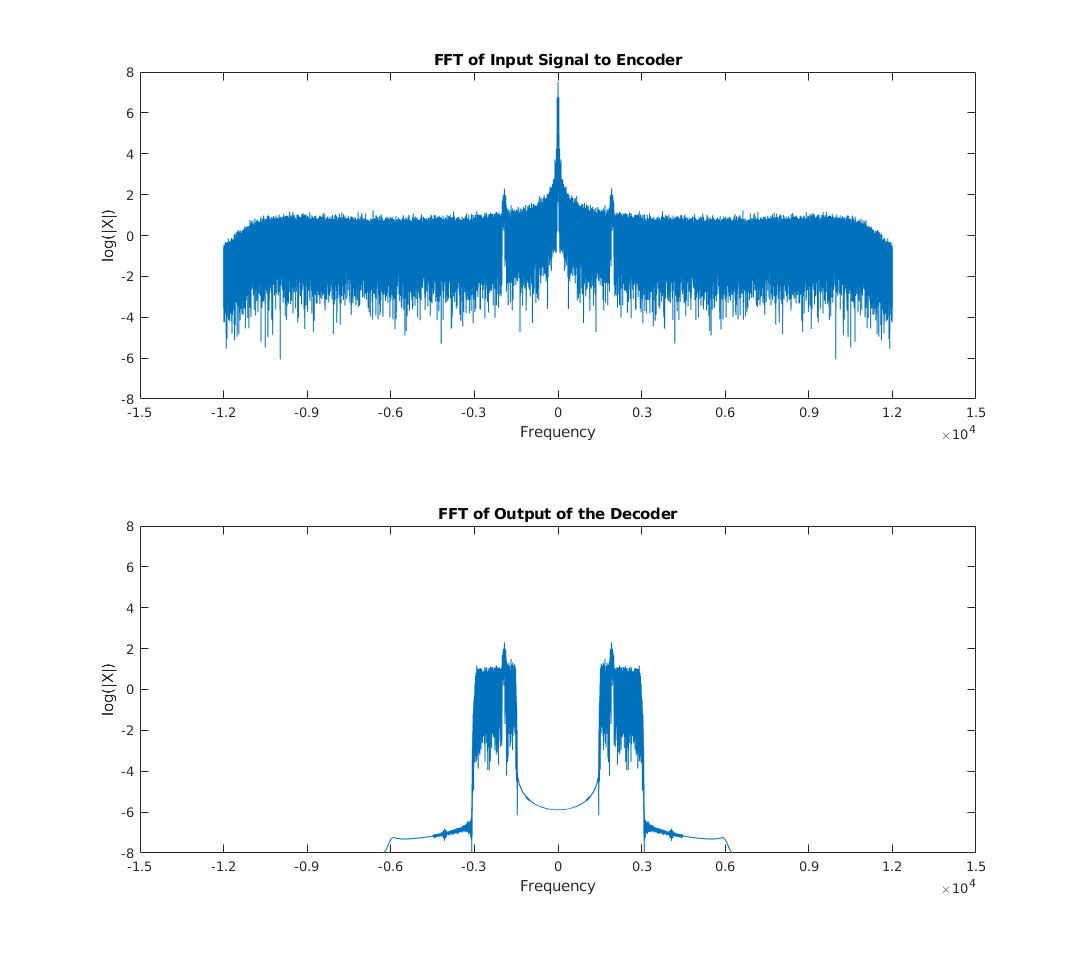

finalOutput_3FFT = log(abs(fftshift(fft(finalOutput_3))));                % Zero-Centered FFT  
finalOutput_3F = (-length(finalOutput_3)/2: length(finalOutput_3)/2-1)...
    /length(finalOutput_3)*Fs3*L;                                       % Zero-Centered Frequency Range 

graph = figure;
subplot(211)
plot(f0Input, inputFFT)
title('FFT of Input Signal to Encoder');
ylabel('log(|X|)')
xlabel('Frequency');
xlim([-15000 15000])
ylim([-8 8])
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
subplot(2,1, 2)
plot(finalOutput_3F, finalOutput_3FFT)
title('FFT of Output of the Decoder');
ylabel('log(|X|)')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.5]);
ax = gca;
set(ax, 'XTick', -15000:3000:15000)
xlim([-15000 15000])
ylim([-8 8])

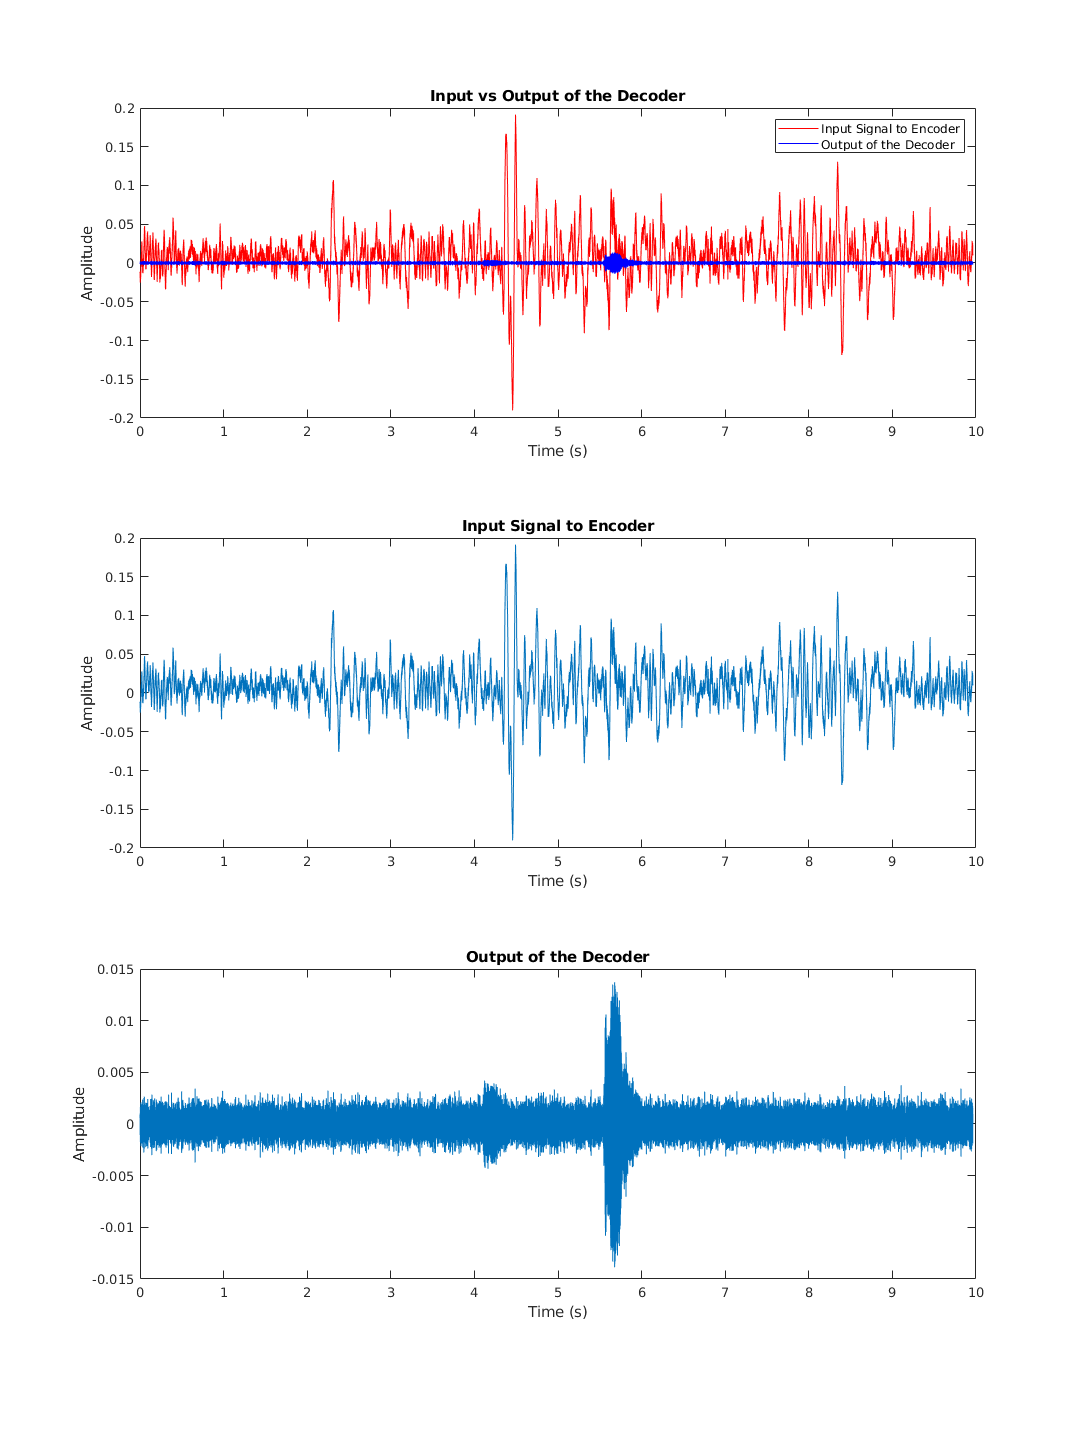

h = figure;
subplot(3,1,1)
plot(timeInput_wDelay_Decoder, inputSig_wDelay_Decoder , '-r')
hold on
plot(timefinalOutput_wDelay, finalOutput_3_wDelay, '-b')
title('Input vs Output of the Decoder')
legend('Input Signal to Encoder','Output of the Decoder')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
set(h,'Units','normalized','Position',[0 0 1 .25]);
hold off
subplot(312)
plot(timeInput_wDelay_Decoder, inputSig_wDelay_Decoder)
title('Input Signal to Encoder')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
subplot(313)
plot(timefinalOutput_wDelay, finalOutput_3_wDelay)
title('Output of the Decoder')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([0 10])
set(h,'Units','normalized','Position',[0 0 1 0.75]);

So, obviously, we are not recreating the input signal anymore like the ones we did in the previous two approaches. And this is because even though the upper-bound in the 0-6000Hz frequecy contains the quail call in the signal, it definitely doesn't contain all content of the original input file to  the encoder.

However, we can use this bond as a denoising method for detection of the quail calls. It was demonstrated that by after sub-band filtering the signal and then just assigning 8 bits to $X_1$ we are actually accomplishing two tasks,

- We are denoising the signal and preserving the quail call. We can now easily detect the calls in the signal in the time-domain (something we definitely couldn't do with the original input signal to the Encoder) using simple methods such as the one shown in the previous part of this project.

- We were also able to reduce the size of our audio file by a factor of 16. This could be very beneficial when we are trying to store large amounts of recordings and all we care about is the quail calls. We can use this method to reduce the size of these large recordings while preserving the quail calls.

And if we wanted to have the audio file at 24kHz again we can always use the Decoder system that we designed above.

### Summary

Using the designed **Encoder **system, **Quantization **with **Approach 3**, and the **Decoder **system we were able to compress the audio file by a factor of 8 and then recreate it again with very high quality. 

If we wanted to use this system to denoise the signal for call detection while compressing it by a factor of 16 we can use **Quantization **with **Approach 2 **it will do a very good job.